# ELEN 133L Lab 8 -- Ayden Dauenhauer and Viet Ha

## Step 1

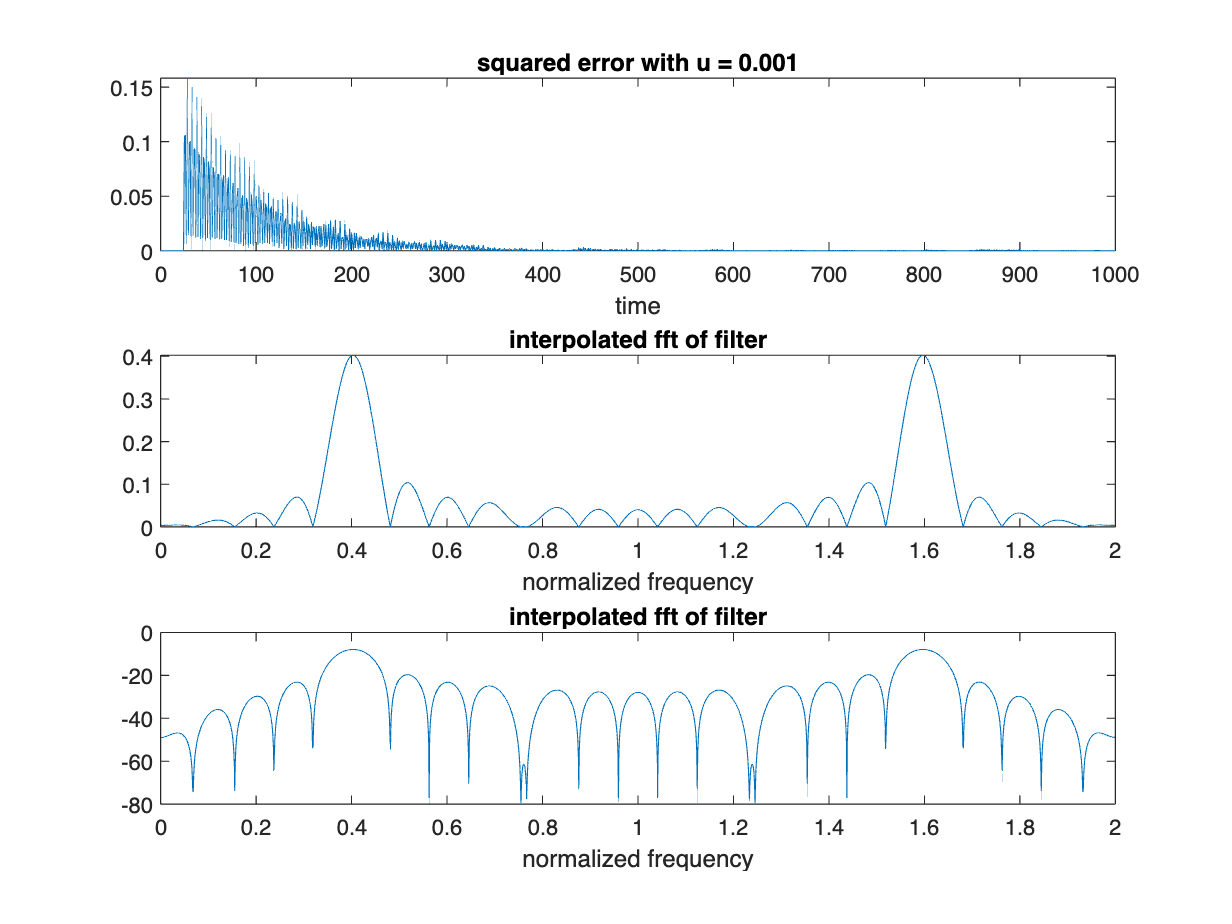

M = 25;
L = 1000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1)) + pi/5); 
y_out = zeros(1, L);
err_out = zeros(1, L);
w = zeros(M, 1);
mu = 0.001;

for n=M:L
    xn = x(n:-1:n-M+1)';
    yn=w' * xn;
    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    w = w + mu*en*xn;
end

figure
subplot(3,1,1);
plot(err_out.*err_out)
xlabel('time');
title('squared error with u = 0.001')

[H, fv] = freqz(w, 1, 2048, "whole");
subplot(3,1,2);
plot(fv/pi, abs(H))
xlabel('normalized frequency');
title('interpolated fft of filter')

subplot(3,1,3);
plot(fv/pi, 20*log10(abs(H)))
xlabel('normalized frequency');
title('interpolated fft of filter')

**Compare this result to the least squares filter result from the homework.**

    The results are close to the least squares filter result from the homework because they both start with high amplitude and converge towards 0 as the time increases.

## Step 2

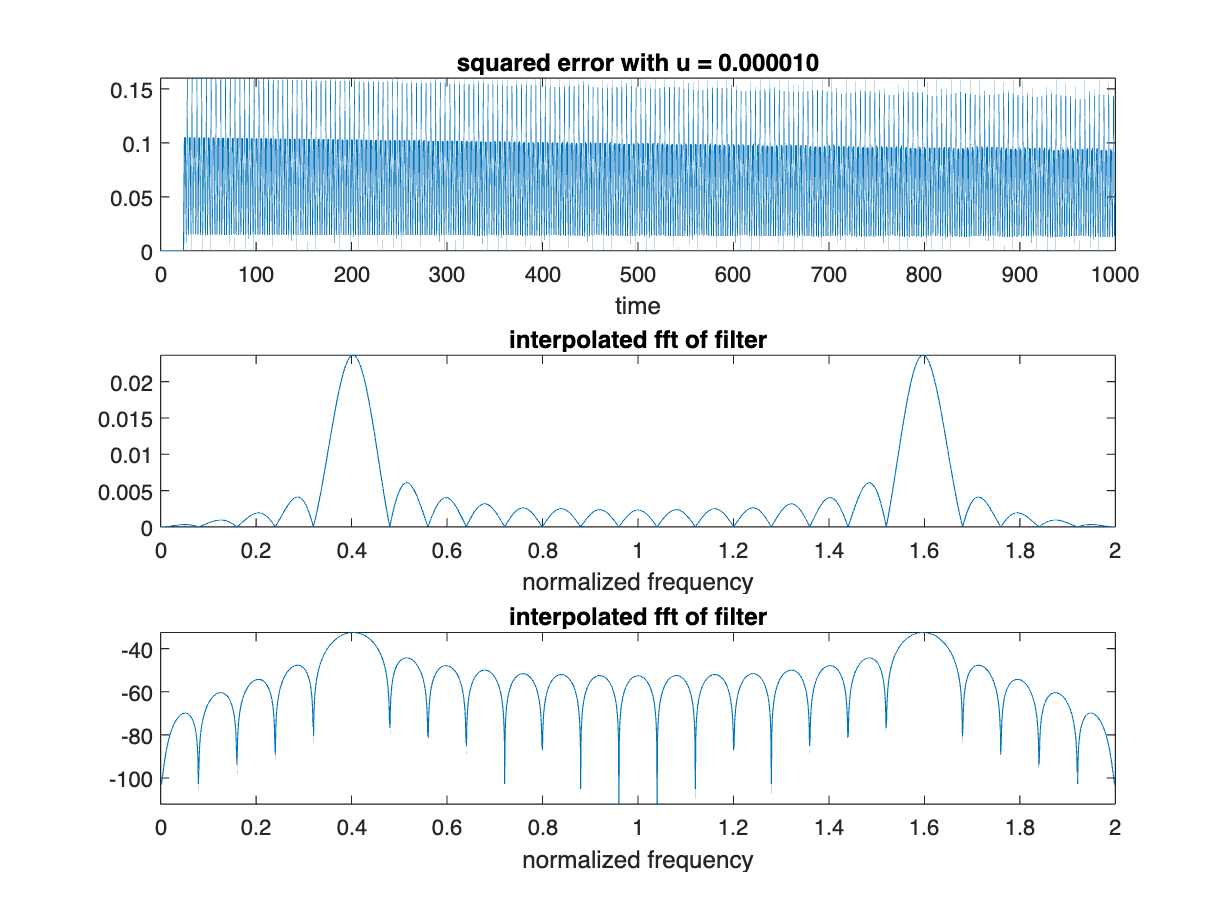

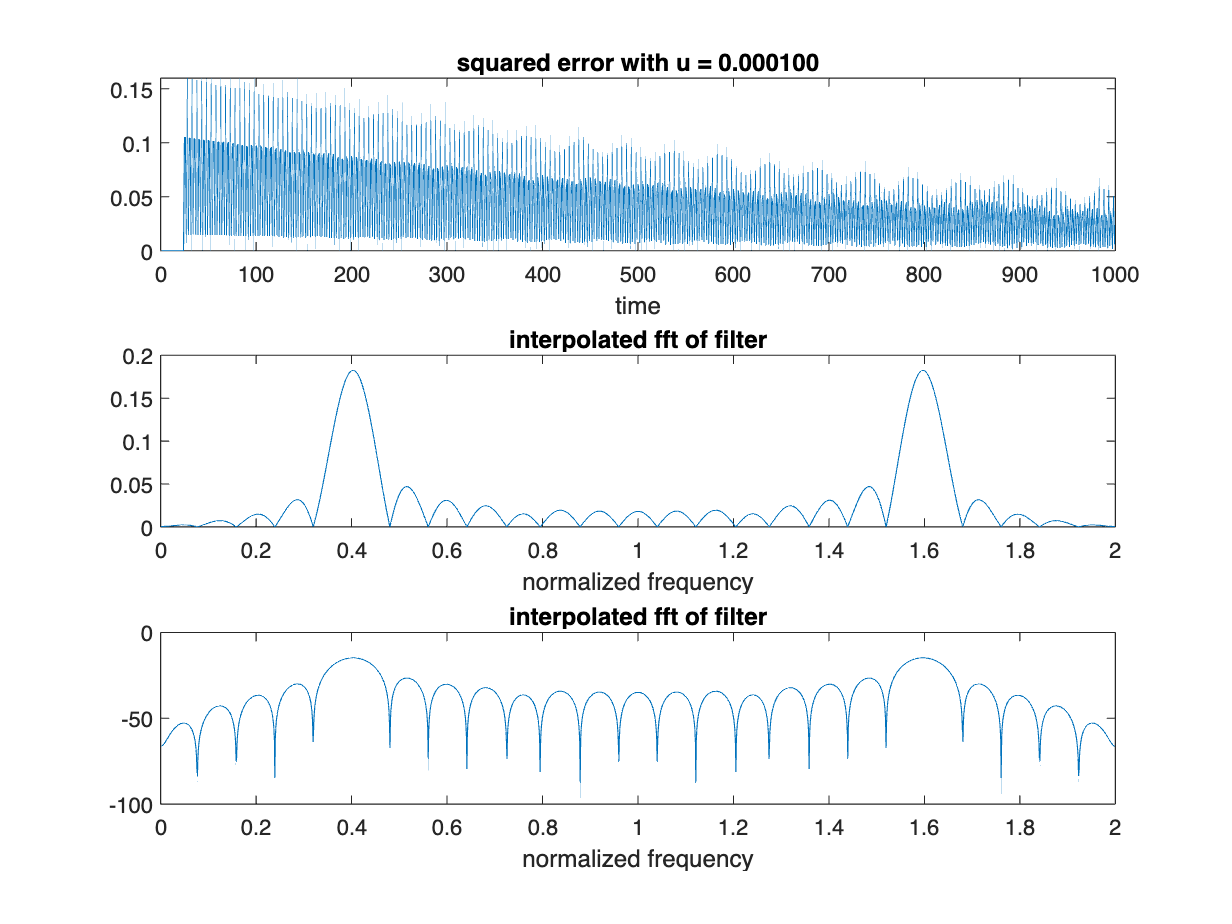

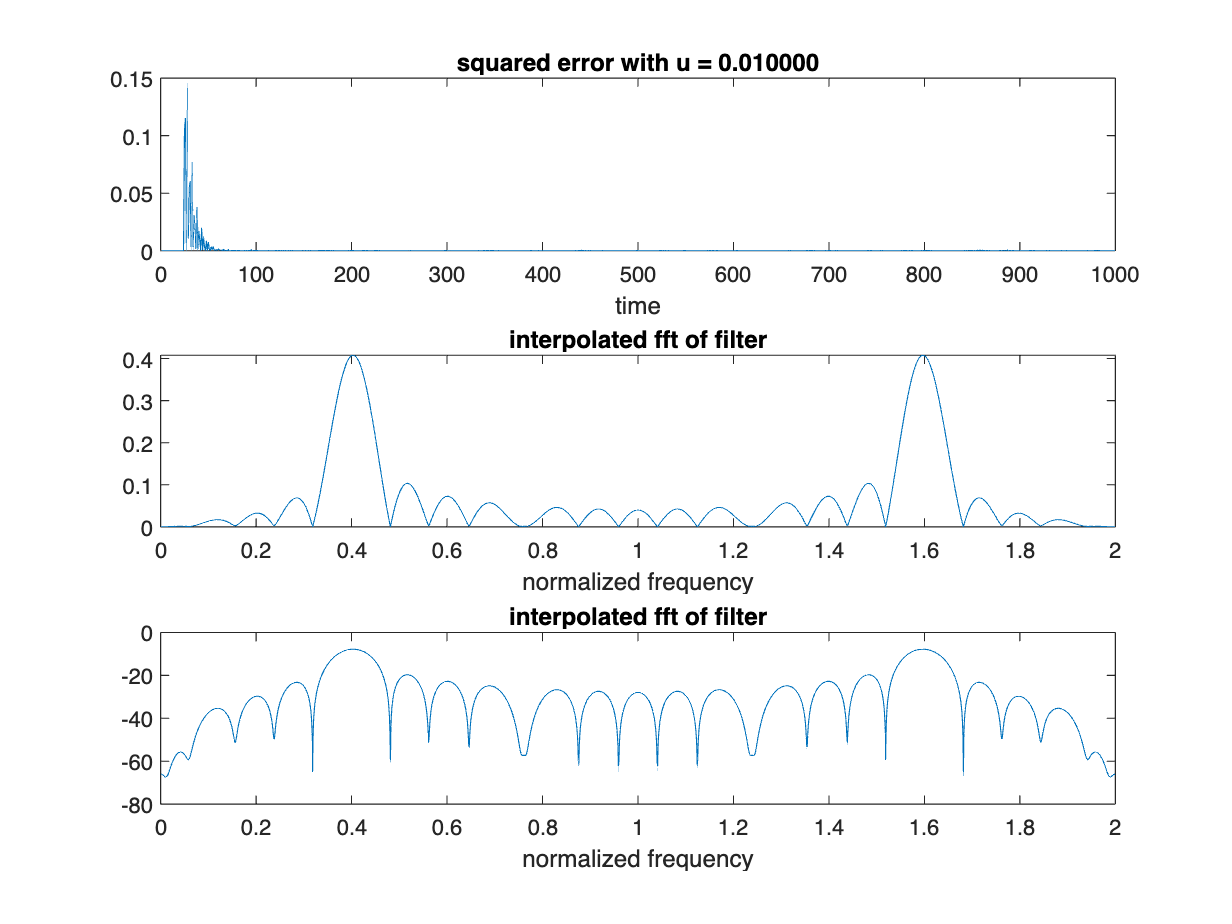

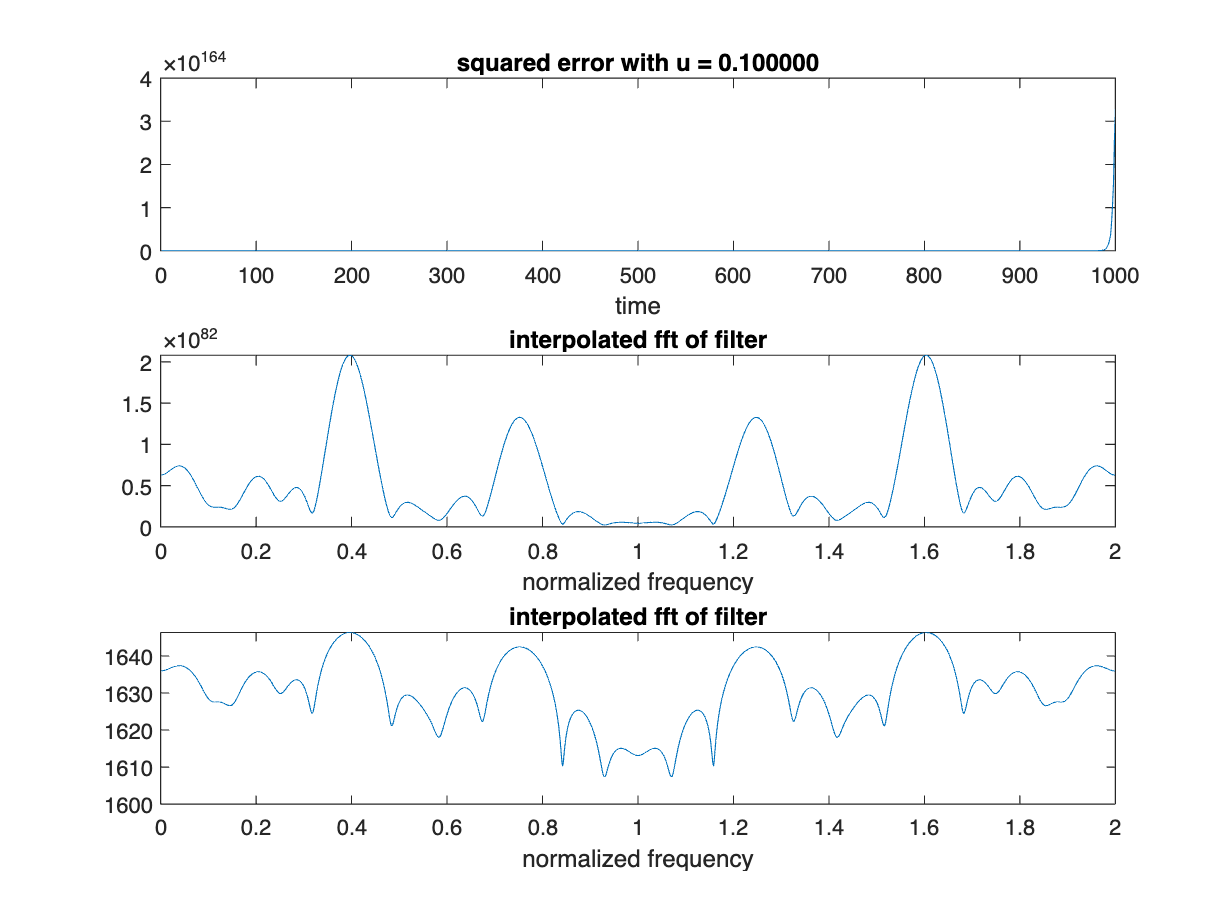

w = zeros(M, 1);
y_out = zeros(1, L);
err_out = zeros(1, L);
mu_arr = [0.00001, 0.0001, 0.01, 0.1];

for i=1:4
    mu = mu_arr(i);
    for n=M:L
        xn = x(n:-1:n-M+1)';
        yn=w' * xn;
        y_out(n) = yn;
        en = d(n) - yn;
        err_out(n) = en;
        w = w + mu*en*xn;
    end

    figure
    subplot(3,1,1);
    plot(err_out.*err_out)
    xlabel('time');
    title(sprintf("squared error with u = %f", mu))
    
    [H, fv] = freqz(w, 1, 2048, "whole");
    subplot(3,1,2);
    plot(fv/pi, abs(H))
    xlabel('normalized frequency');
    title('interpolated fft of filter')

    subplot(3,1,3);
    plot(fv/pi, 20*log10(abs(H)))
    xlabel('normalized frequency');
    title('interpolated fft of filter')
    
    w = zeros(M, 1);
    y_out = zeros(1, L);
    err_out = zeros(1, L);
end

**What is the lowest value of the squared error? If the error goes to close to zero, how many iterations does it take?**

    mu = 0.00001: lowest value of the squared error = 0.1

    mu = 0.0001: lowest value of the squared error = 0.05

    mu = 0.01: lowest value of the squared error = 0

    mu = 0.1: lowest value of the squared error = 0

**After L data samples how much does the shape of the fft of the filter look like the least squares filter fft from the class lecture slides?**

    mu = 0.00001: The shape of the fft looks close to the lecture slides because mu is smallest which means it has the smallest stepping sizes and allows it to converge easiest.

    mu = 0.0001: The shape of the fft looks less like the lecture slides because mu is slightly bigger.

    mu = 0.01: The shape of the fft looks even more less like the lecture slides because mu is bigger again.

    mu = 0.1: The shape of the fft looks least like the lecture slides because mu is the biggest.

**What is the maximum value of the adaptive filter’s fft magnitude? How does that compare to the least squares fft?**

    mu = 0.00001: maximum value of the adaptive filter’s fft magnitude = 0.025

    mu = 0.0001: lowest value of the squared error = 0.18

    mu = 0.01: lowest value of the squared error = 0.4

    mu = 0.1: lowest value of the squared error = 2x10^82

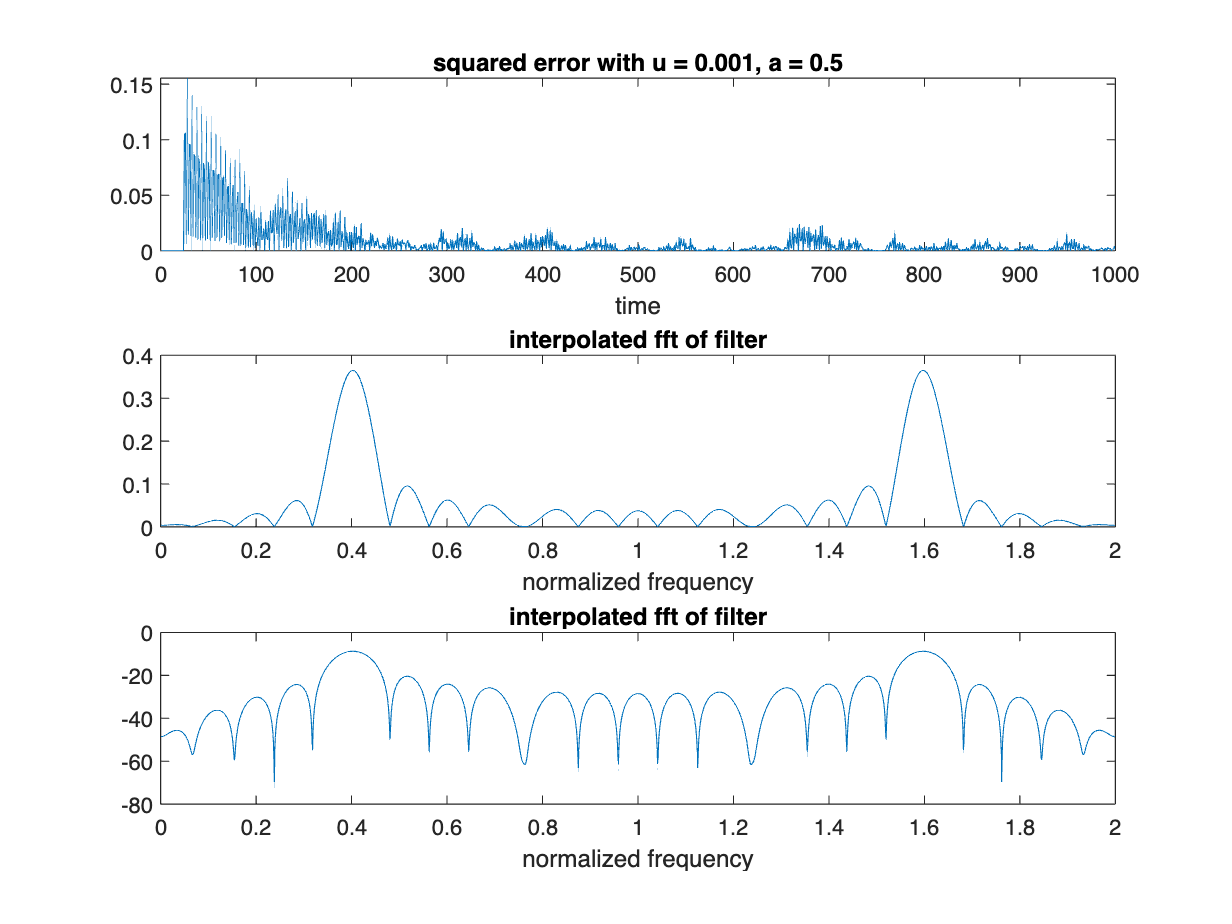

a = 0.5;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1)) + pi/5); 
y_out = zeros(1, L);
err_out = zeros(1, L);
w = zeros(M, 1);
mu = 0.001;

for n=M:L
    xn = x(n:-1:n-M+1)';
    yn=w' * xn;
    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    w = w + mu*en*xn;
end

figure
subplot(3,1,1);
plot(err_out.*err_out)
xlabel('time');
title('squared error with u = 0.001, a = 0.5')

[H, fv] = freqz(w, 1, 2048, "whole");
subplot(3,1,2);
plot(fv/pi, abs(H))
xlabel('normalized frequency');
title('interpolated fft of filter')

subplot(3,1,3);
plot(fv/pi, 20*log10(abs(H)))
xlabel('normalized frequency');
title('interpolated fft of filter')

**How do these results compare to Step 1 results? Why do you think the squared error curve is different?**

    The squared error curve is different because a increased which means there is more randomness/noise.

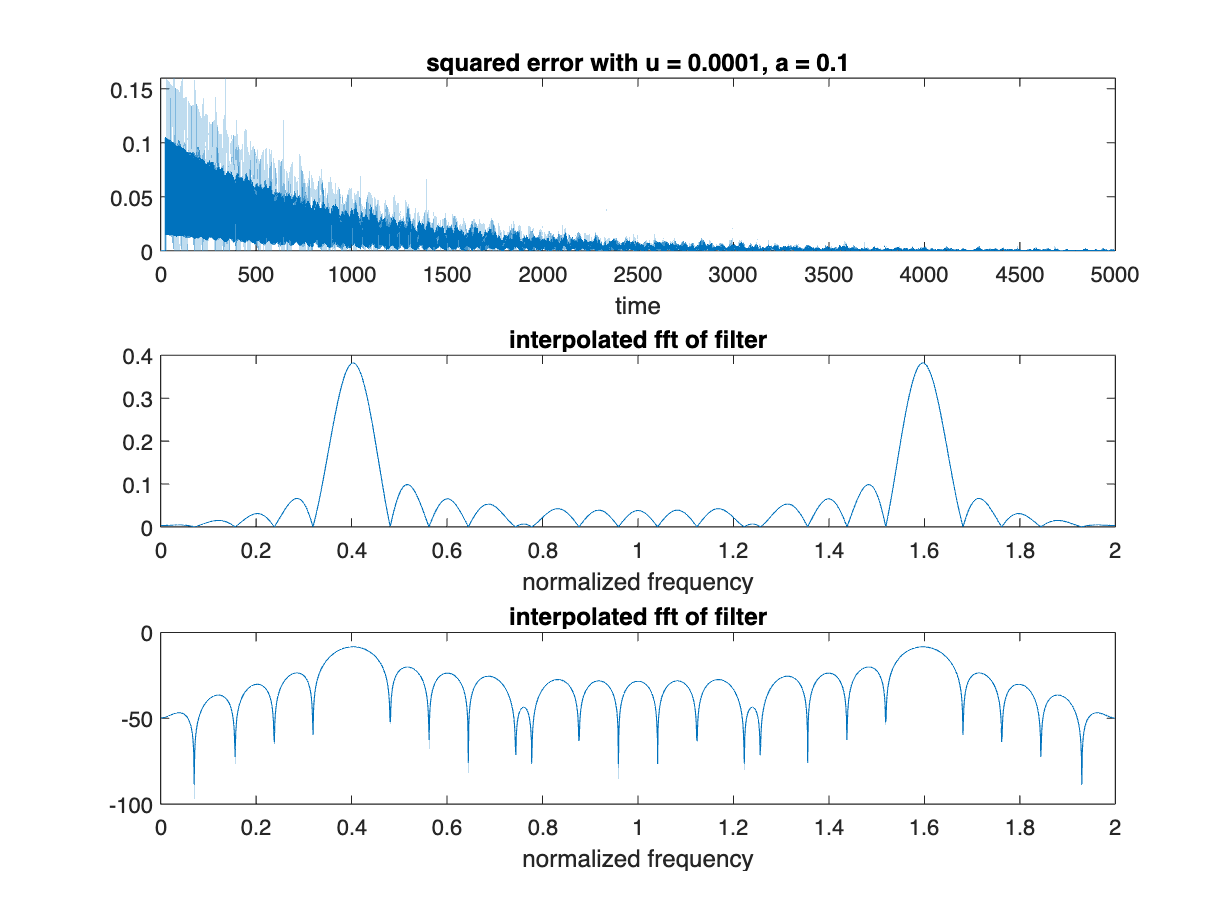

L = 5000;
a = 0.1;
x = cos(2*pi*0.2*(0:(L-1))) + cos(2*pi*0.38*(0:(L-1)))+a*randn(1,L);
d = 0.4*cos(2*pi*0.2*(0:(L-1)) + pi/5); 
y_out = zeros(1, L);
err_out = zeros(1, L);
w = zeros(M, 1);
mu = 0.0001;

for n=M:L
    xn = x(n:-1:n-M+1)';
    yn=w' * xn;
    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    w = w + mu*en*xn;
end

figure
subplot(3,1,1);
plot(err_out.*err_out)
xlabel('time');
title('squared error with u = 0.0001, a = 0.1')

[H, fv] = freqz(w, 1, 2048, "whole");
subplot(3,1,2);
plot(fv/pi, abs(H))
xlabel('normalized frequency');
title('interpolated fft of filter')
subplot(3,1,3);
plot(fv/pi, 20*log10(abs(H)))
xlabel('normalized frequency');
title('interpolated fft of filter')

**Compare the results to the result earlier in this step which had the same value of mu and a, but had L = 1000.**

    The results are pretty similar, however now there is a longer length so more data can be sampled. 

## Step 3

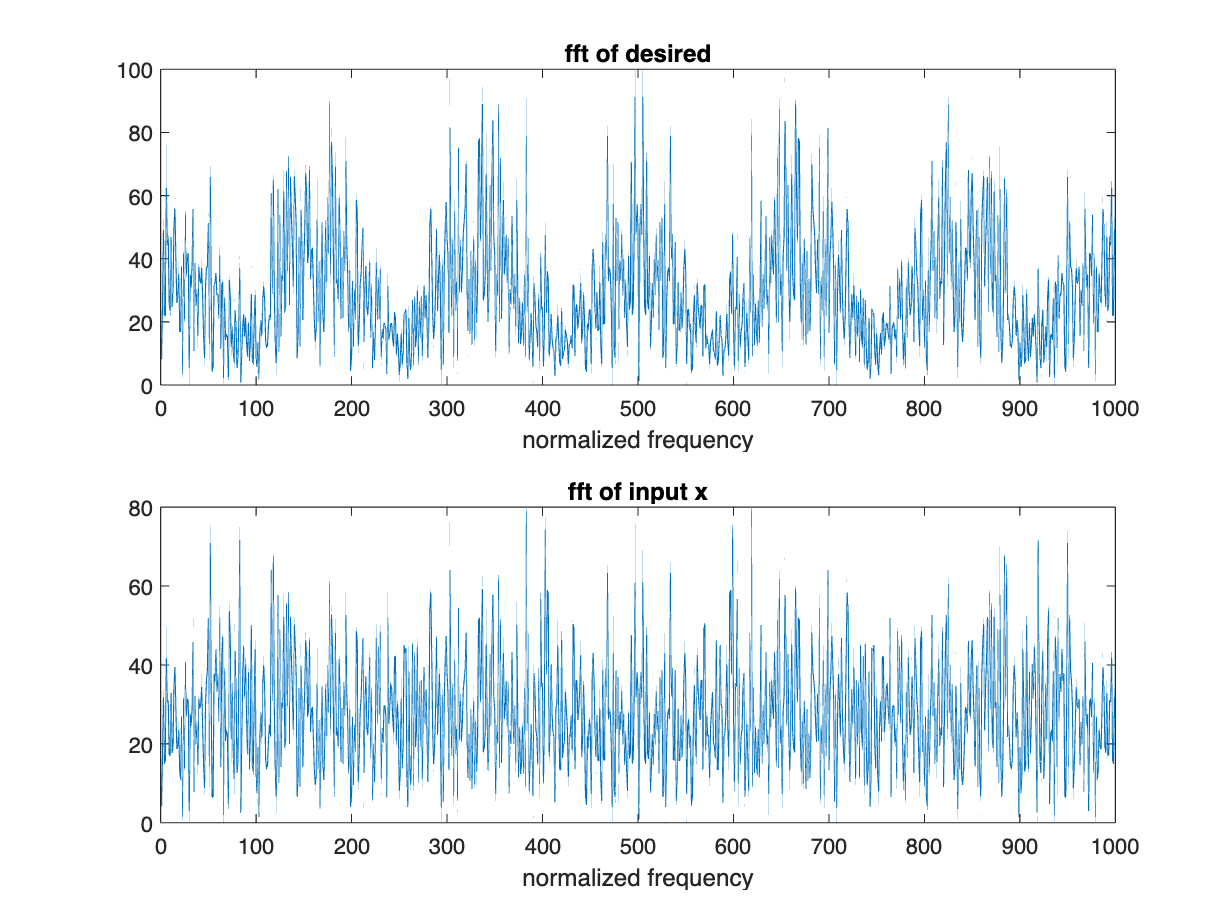

M = 25;
L = 1000;
h = [1, 0, 0, 0, 0, 0, 0.5];
x = randn(1,L);
x_unk = conv(h,x);
d = x_unk(1: end- length(h)+1);

figure;
subplot(2,1,1);
plot(abs(fft(d)))
xlabel('normalized frequency');
title('fft of desired')

subplot(2,1,2);
plot(abs(fft(x)))
xlabel('normalized frequency');
title('fft of input x')

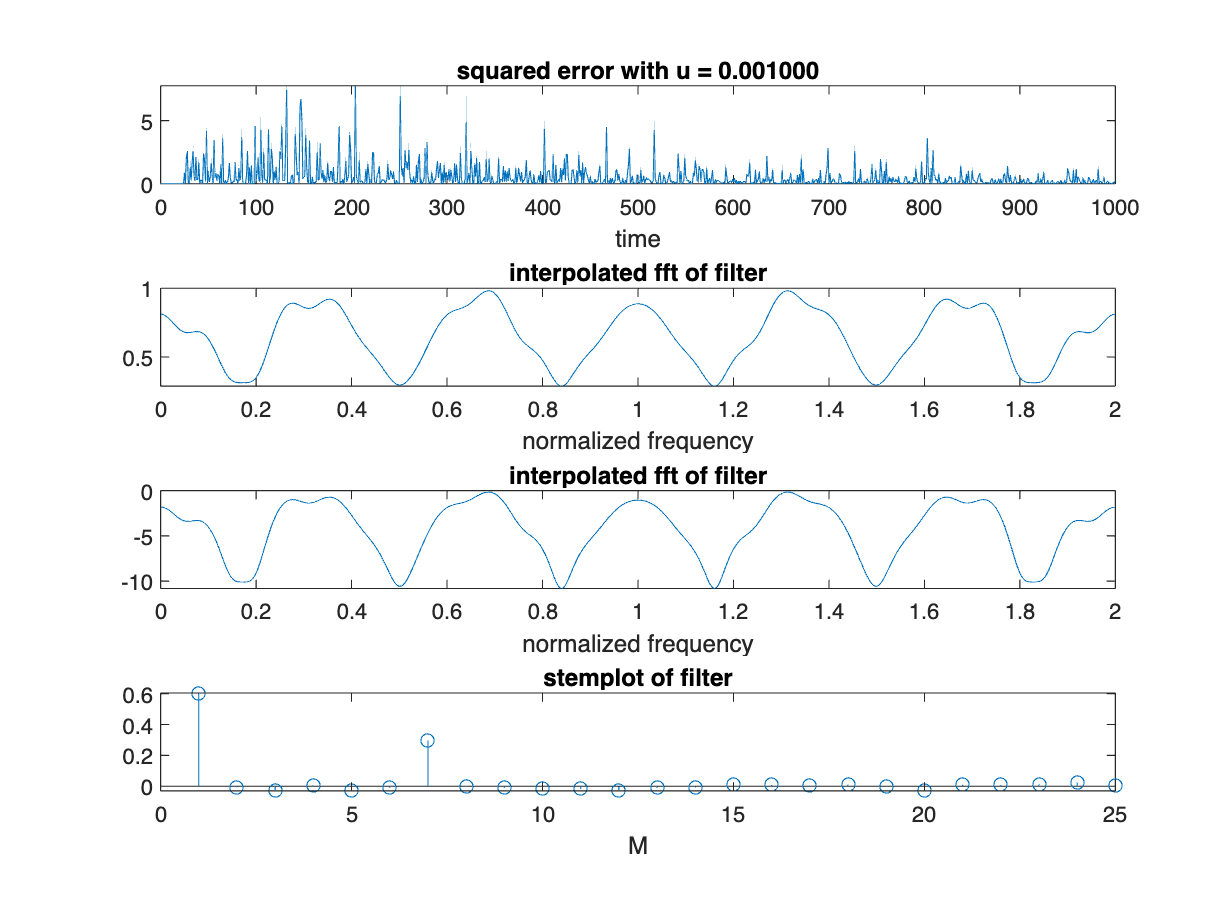

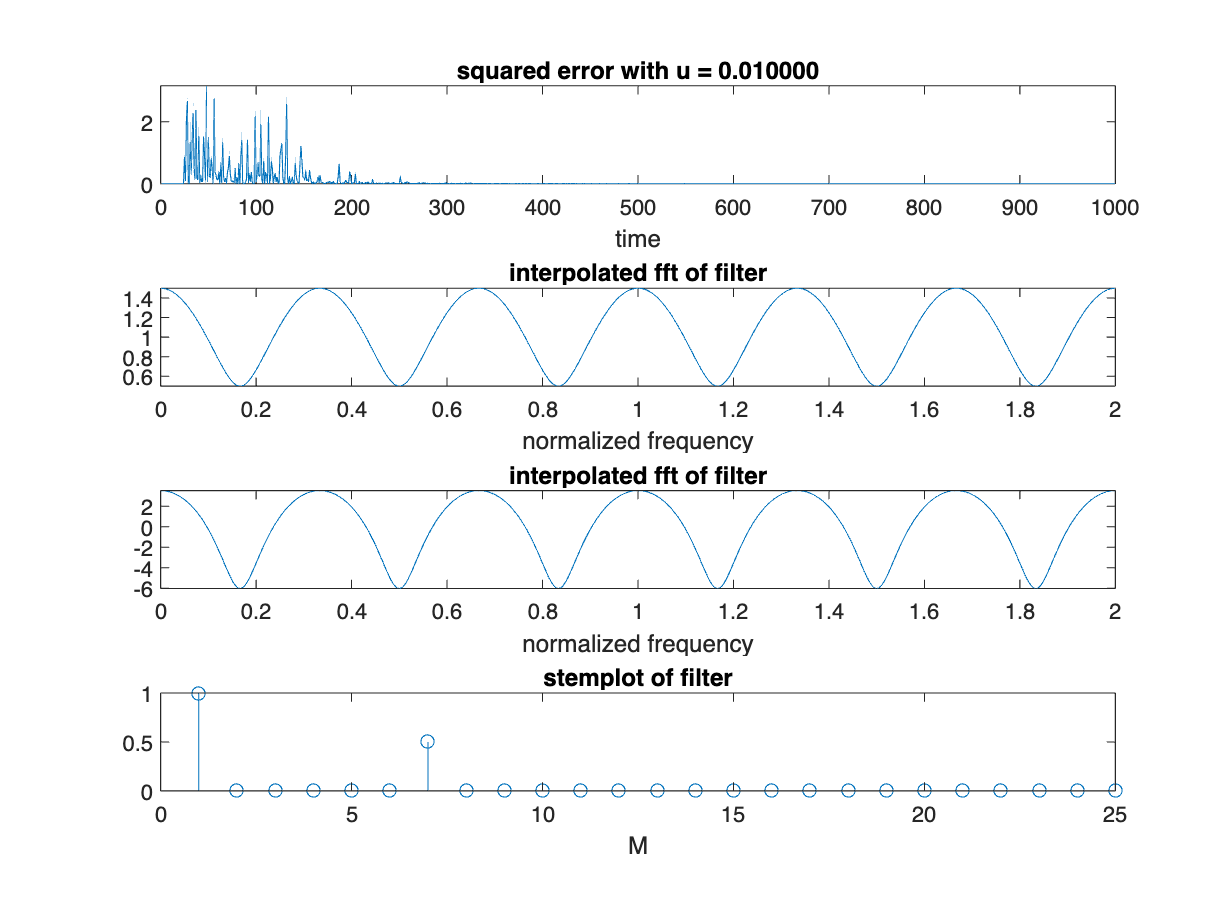

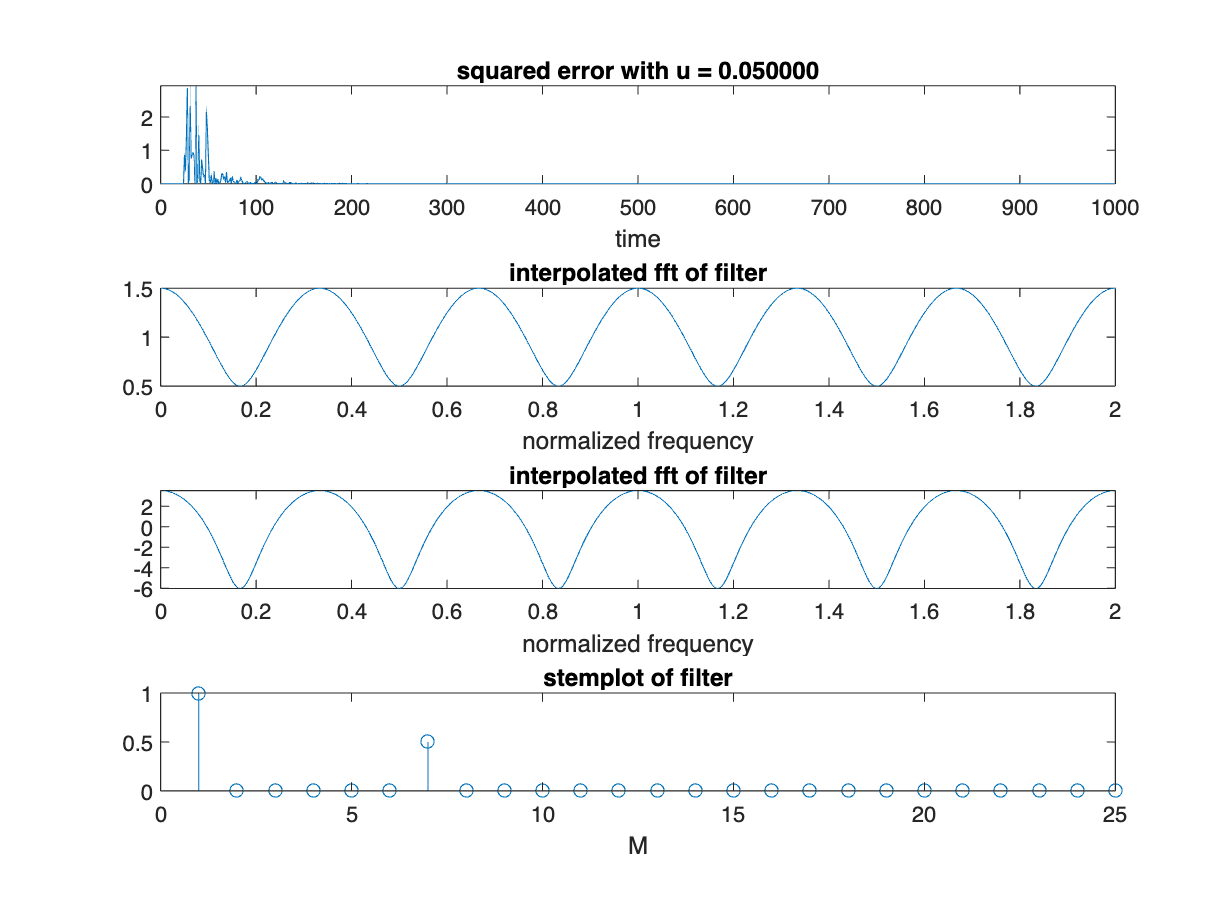

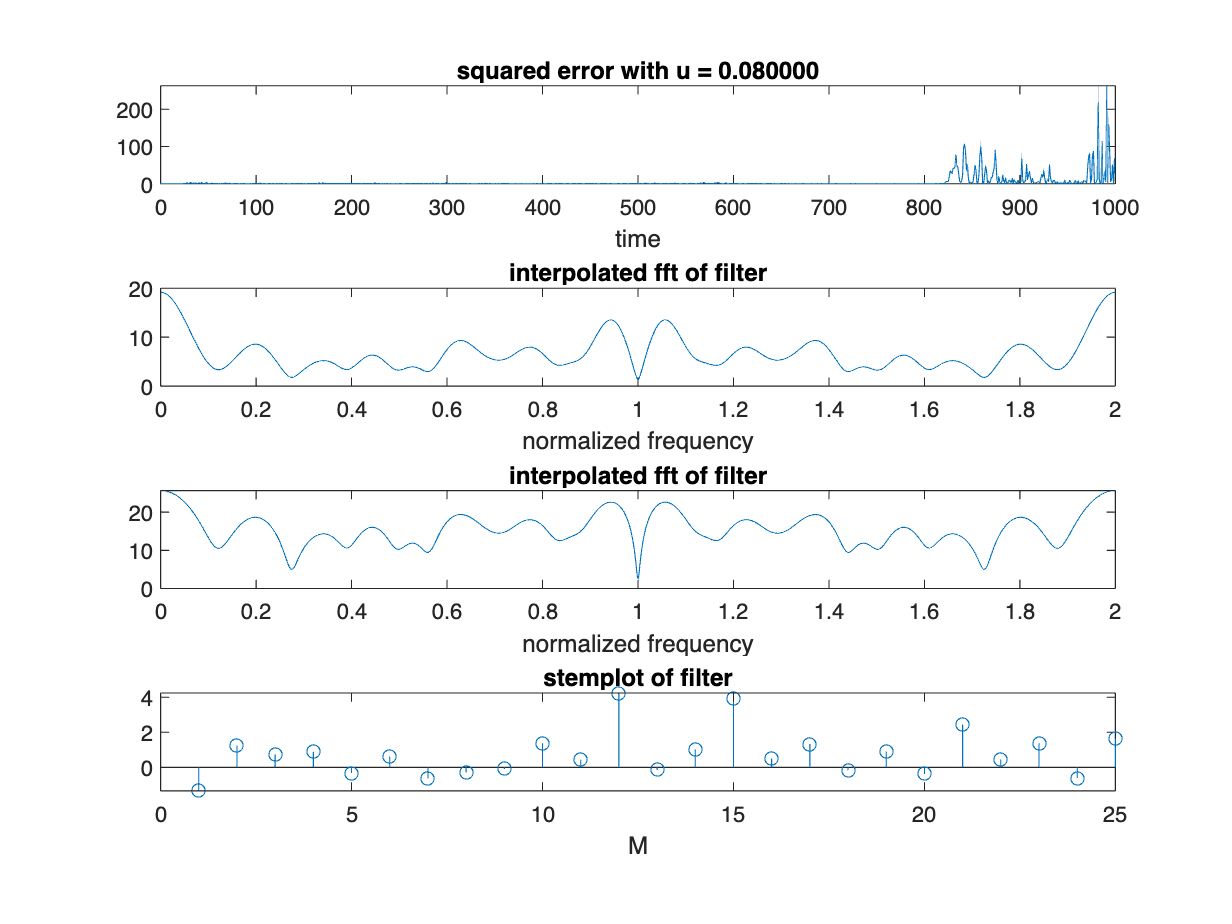

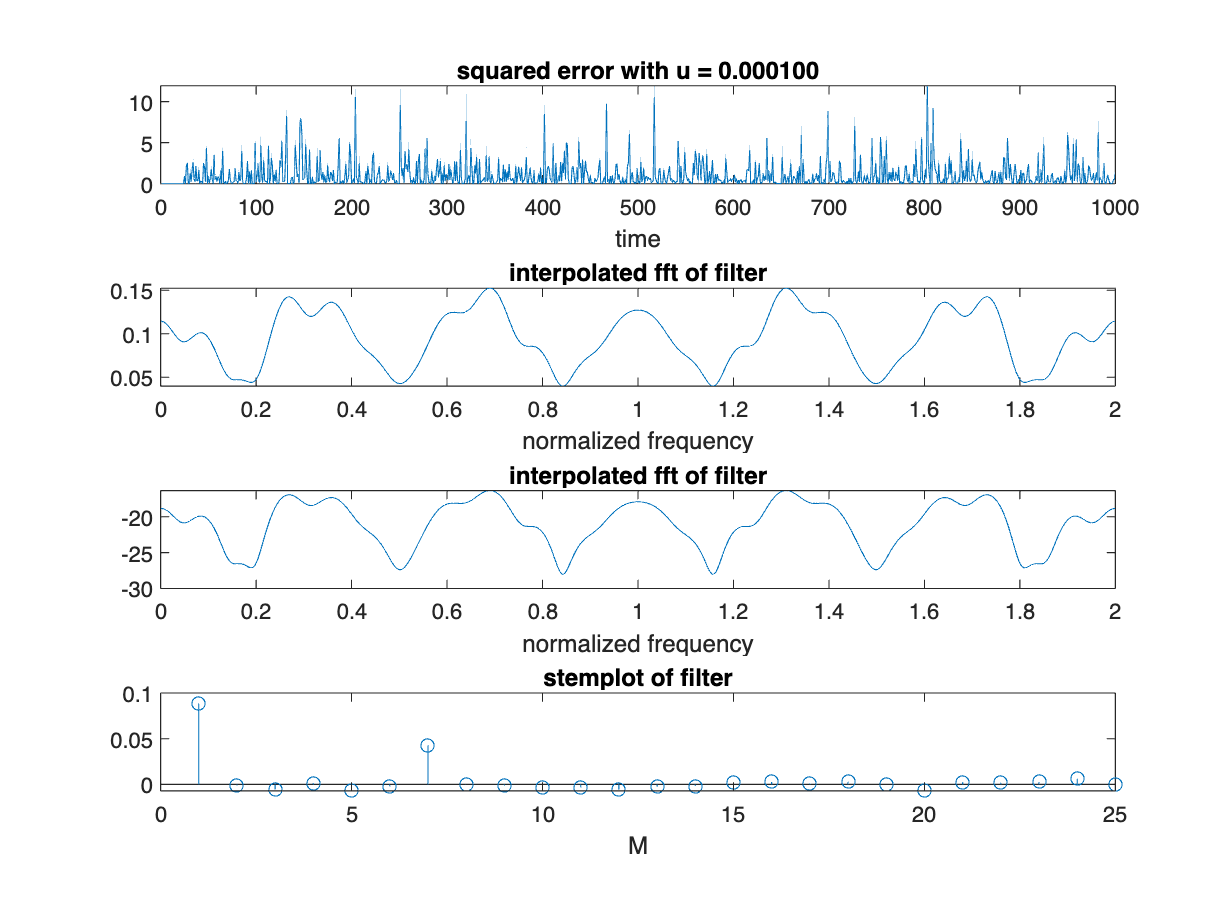

w = zeros(M, 1);
y_out = zeros(1, L);
err_out = zeros(1, L);
mu_arr = [0.001, 0.01, 0.05, 0.08, 0.0001];

for i=1:5
    mu = mu_arr(i);
    for n=M:L
        xn = x(n:-1:n-M+1)';
        yn=w' * xn;
        y_out(n) = yn;
        en = d(n) - yn;
        err_out(n) = en;
        w = w + mu*en*xn;
    end

    figure
    subplot(4,1,1);
    plot(err_out.*err_out)
    xlabel('time');
    title(sprintf("squared error with u = %f", mu))
    
    [H, fv] = freqz(w, 1, 2048, "whole");
    subplot(4,1,2);
    plot(fv/pi, abs(H))
    xlabel('normalized frequency');
    title('interpolated fft of filter')
    
    subplot(4,1,3);
    plot(fv/pi, 20*log10(abs(H)))
    xlabel('normalized frequency');
    title('interpolated fft of filter')
    
    subplot(4,1,4);
    stem(w)
    xlabel('M');
    title('stemplot of filter')

    w = zeros(M, 1);
    y_out = zeros(1, L);
    err_out = zeros(1, L);
end

**Compare the filter w with the unknown filter h. How similar is it?**

    From the stem plot, w and h are similar because there is high amplitude at the first index and at the 7th index, which matches h's magnitudes.

**What is the error level at the end of the adaptation loop?**

    The squared error is decreasing as L increases. 

**Rerun the filter with mu = 0.01 and compare.**

    There is much less error and it seems to reach 0 at the end.

**Describe the results you obtain with mu = 0.05, 0.08, and 0.0001.**

    mu = 0.05 is also very close and have an error of 0 at the end.

    mu = 0.08 has low error at the beginning but high error at the end.

    mu = 0.0001 has consistantly high error.

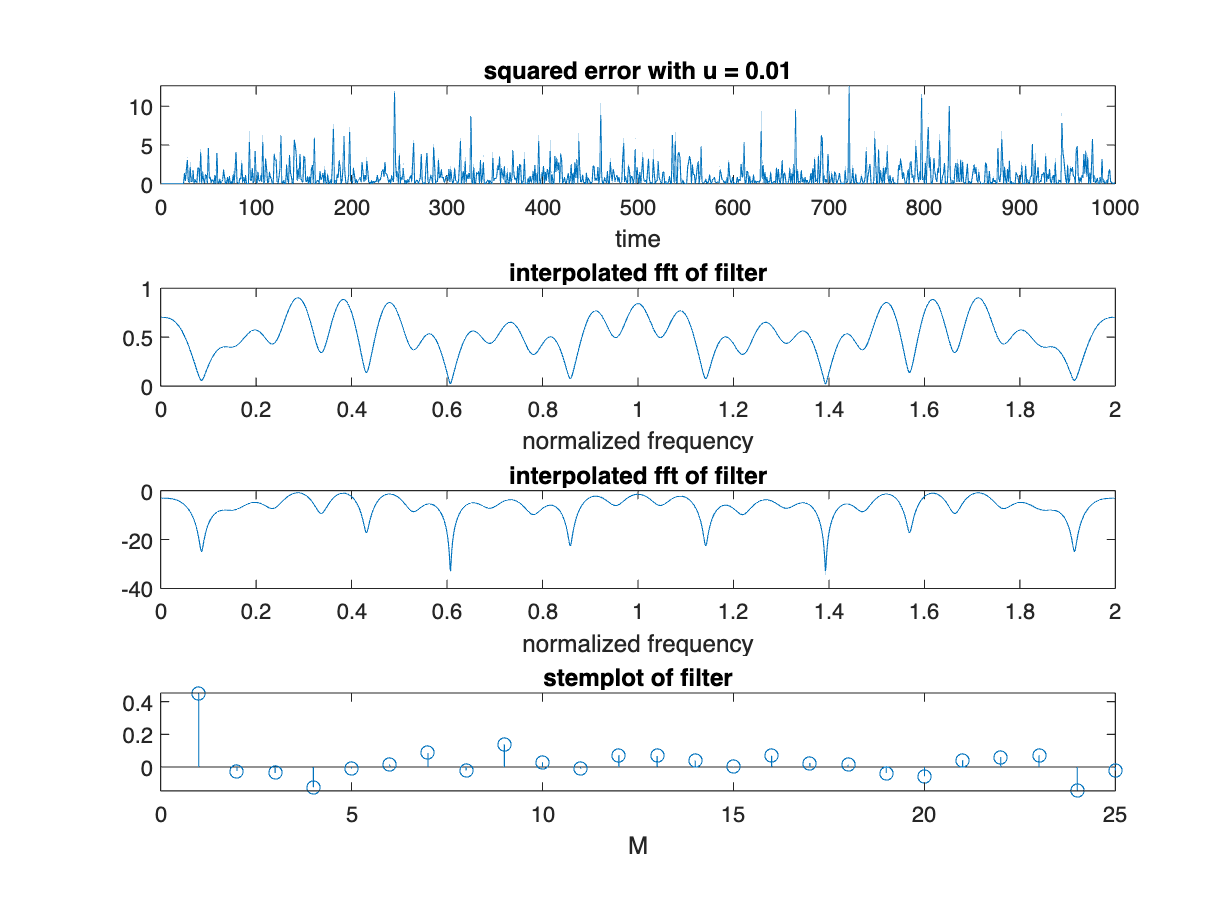

mu = 0.01;
d = x_unk(length(h):end);

for n=M:L
    xn = x(n:-1:n-M+1)';
    yn=w' * xn;
    y_out(n) = yn;
    en = d(n) - yn;
    err_out(n) = en;
    w = w + mu*en*xn;
end

figure
subplot(4,1,1);
plot(err_out.*err_out)
xlabel('time');
title('squared error with u = 0.01')

[H, fv] = freqz(w, 1, 2048, "whole");
subplot(4,1,2);
plot(fv/pi, abs(H))
xlabel('normalized frequency');
title('interpolated fft of filter')

subplot(4,1,3);
plot(fv/pi, 20*log10(abs(H)))
xlabel('normalized frequency');
title('interpolated fft of filter')

subplot(4,1,4);
stem(w)
xlabel('M');
title('stemplot of filter')

**Describe the output and explain.**

    There is high error and the stem plot seems to be oscillating.

## **Step 4**

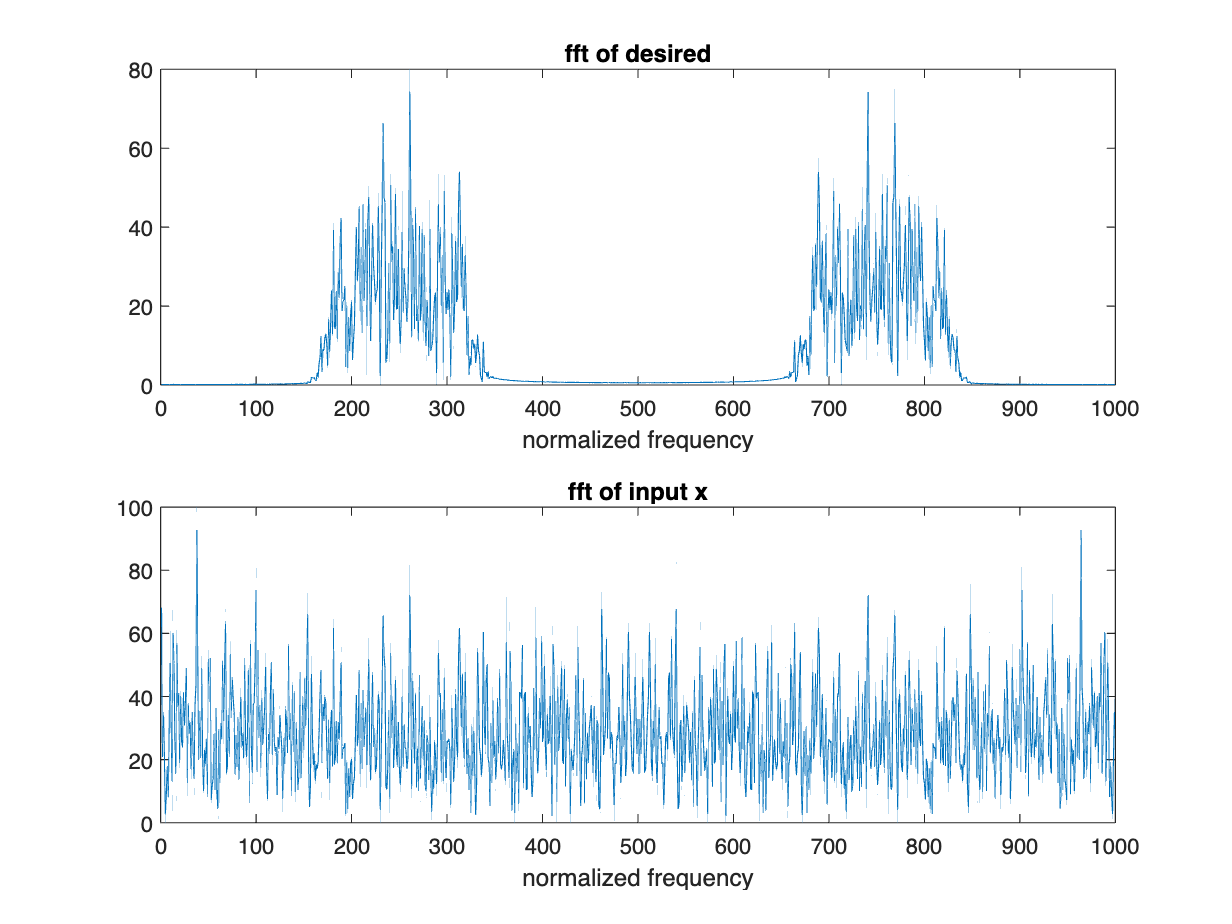

M = 25;
L = 1000;
f_pm = [0, 1200, 1600, 2400, 2800, 4000]/4000;
a_pm = [0,0,1,1,0,0];
n_pm = 64;
b_pm = firpm(n_pm, f_pm, a_pm);
x = randn(1,L);
x_unk = conv(b_pm, x);
d = x_unk(1: end- length(b_pm)+1);

figure;
subplot(2,1,1);
plot(abs(fft(d)))
xlabel('normalized frequency');
title('fft of desired')

subplot(2,1,2);
plot(abs(fft(x)))
xlabel('normalized frequency');
title('fft of input x')

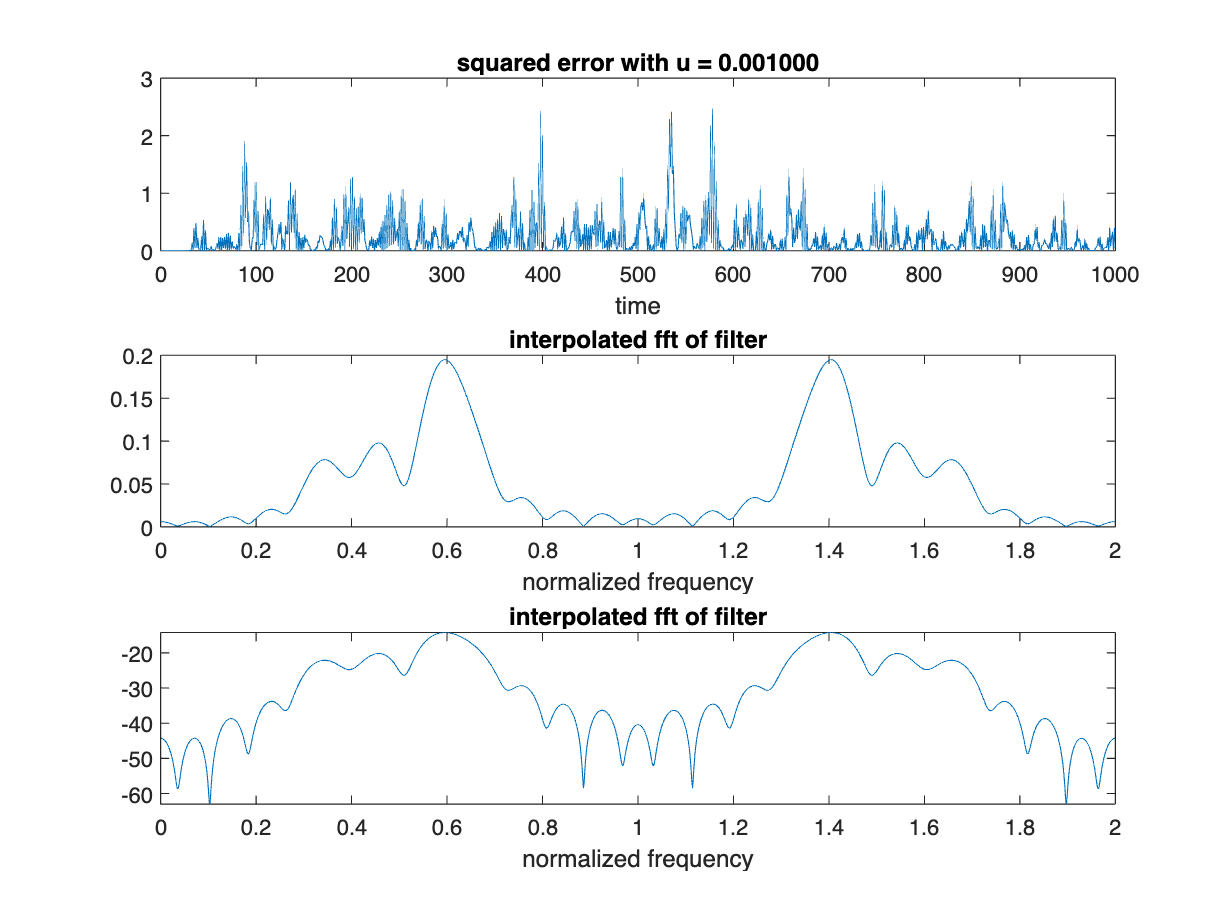

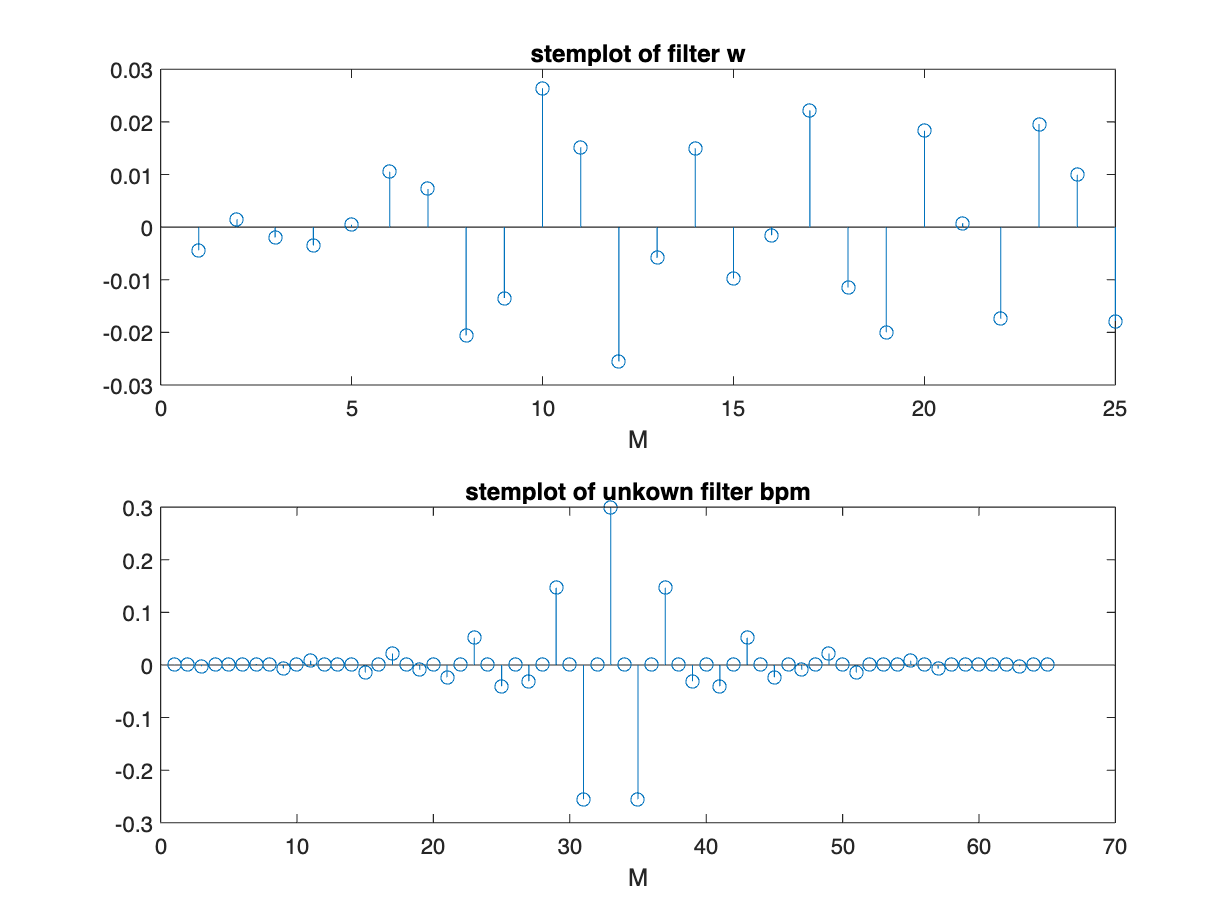

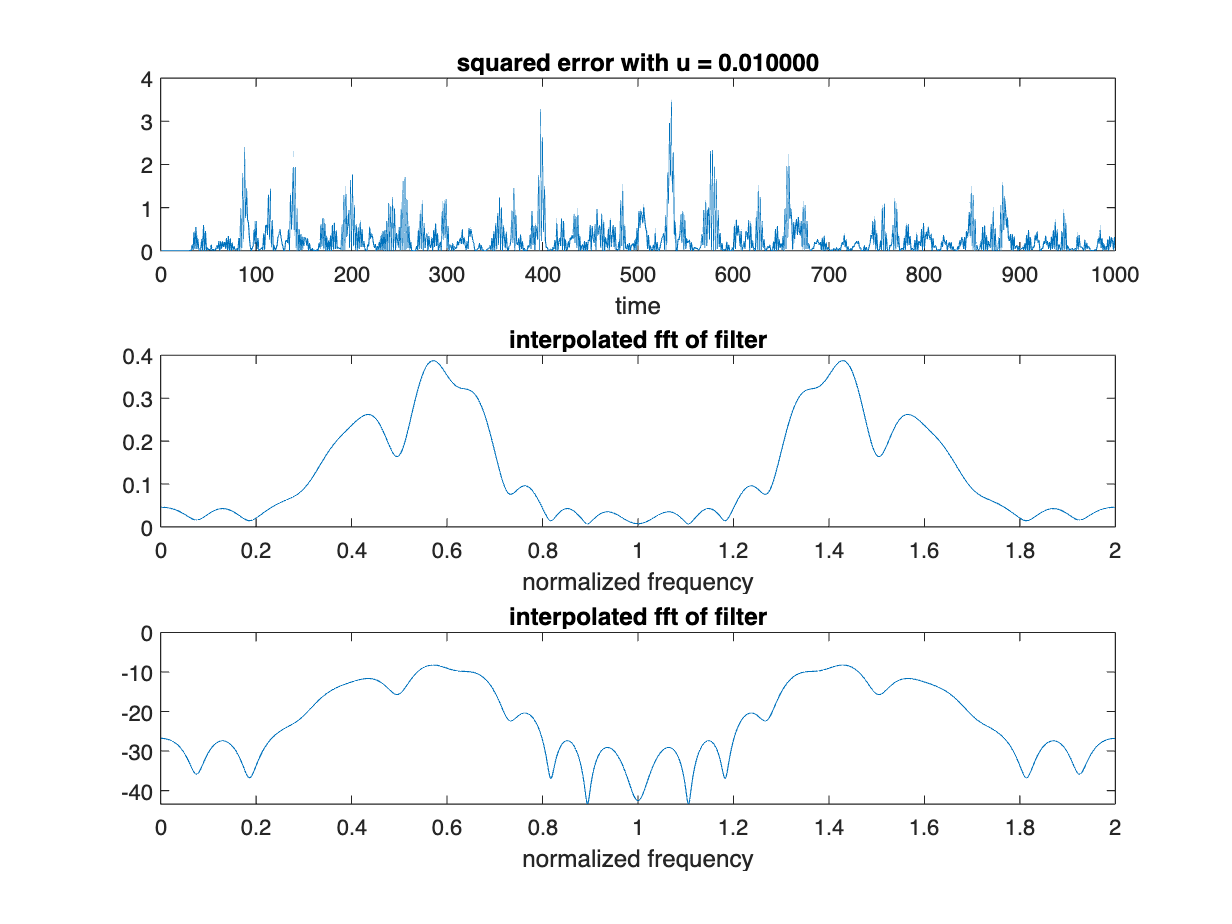

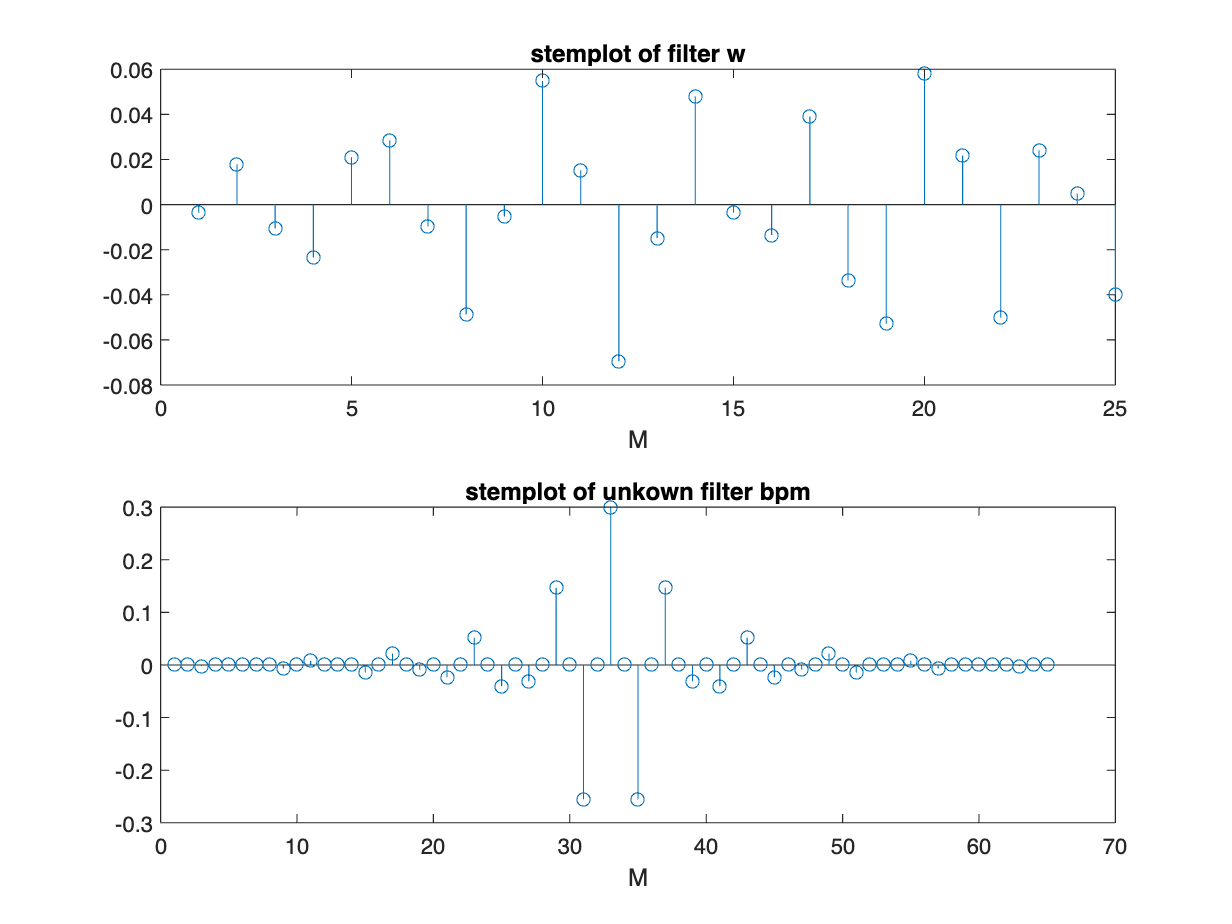

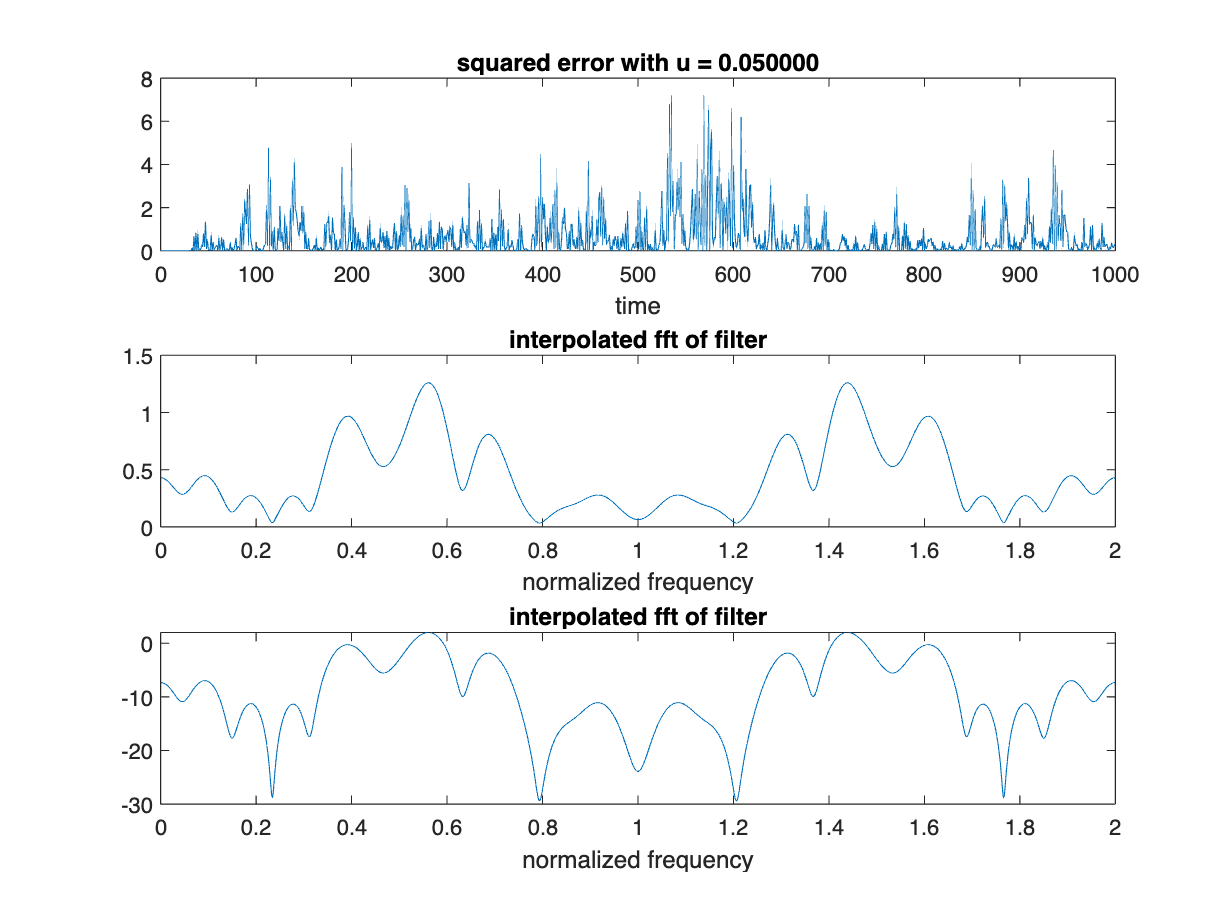

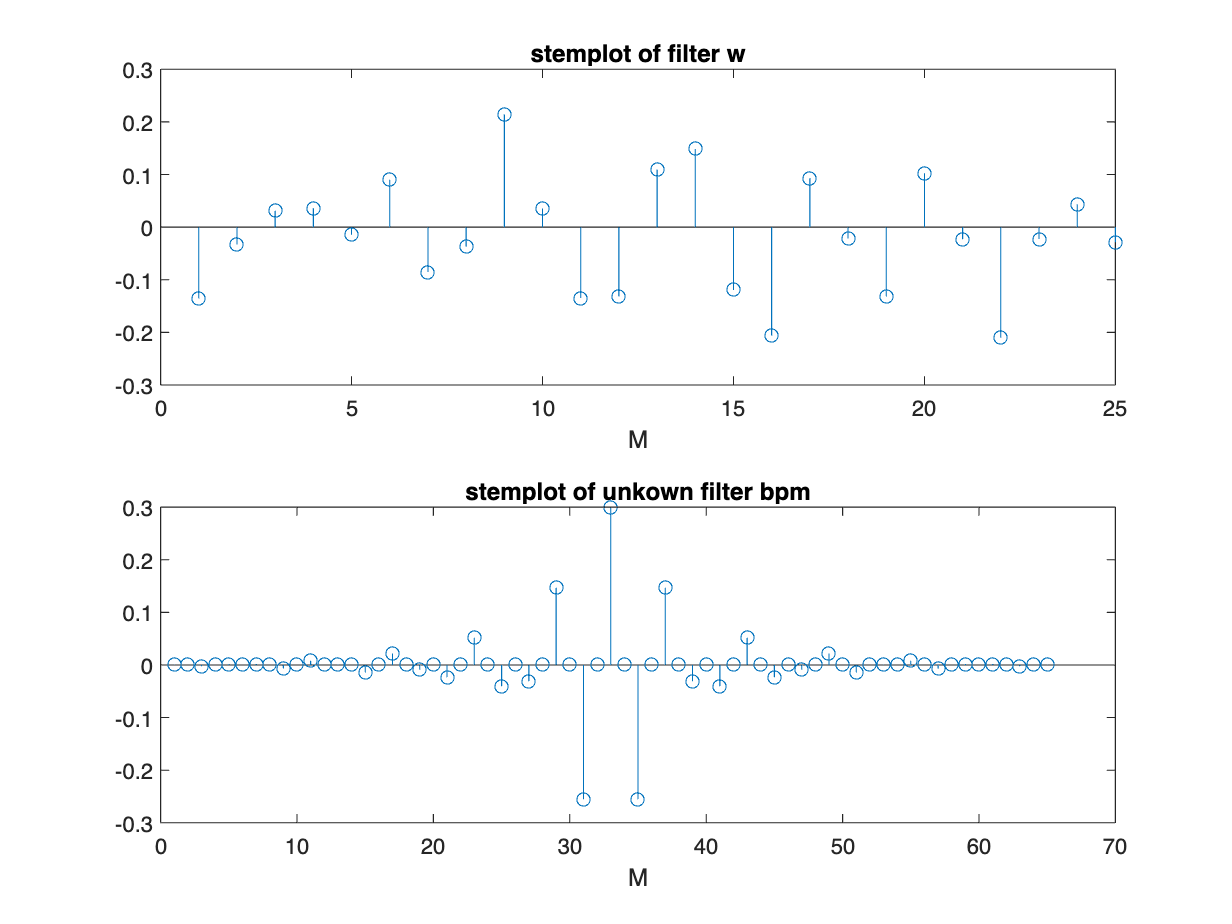

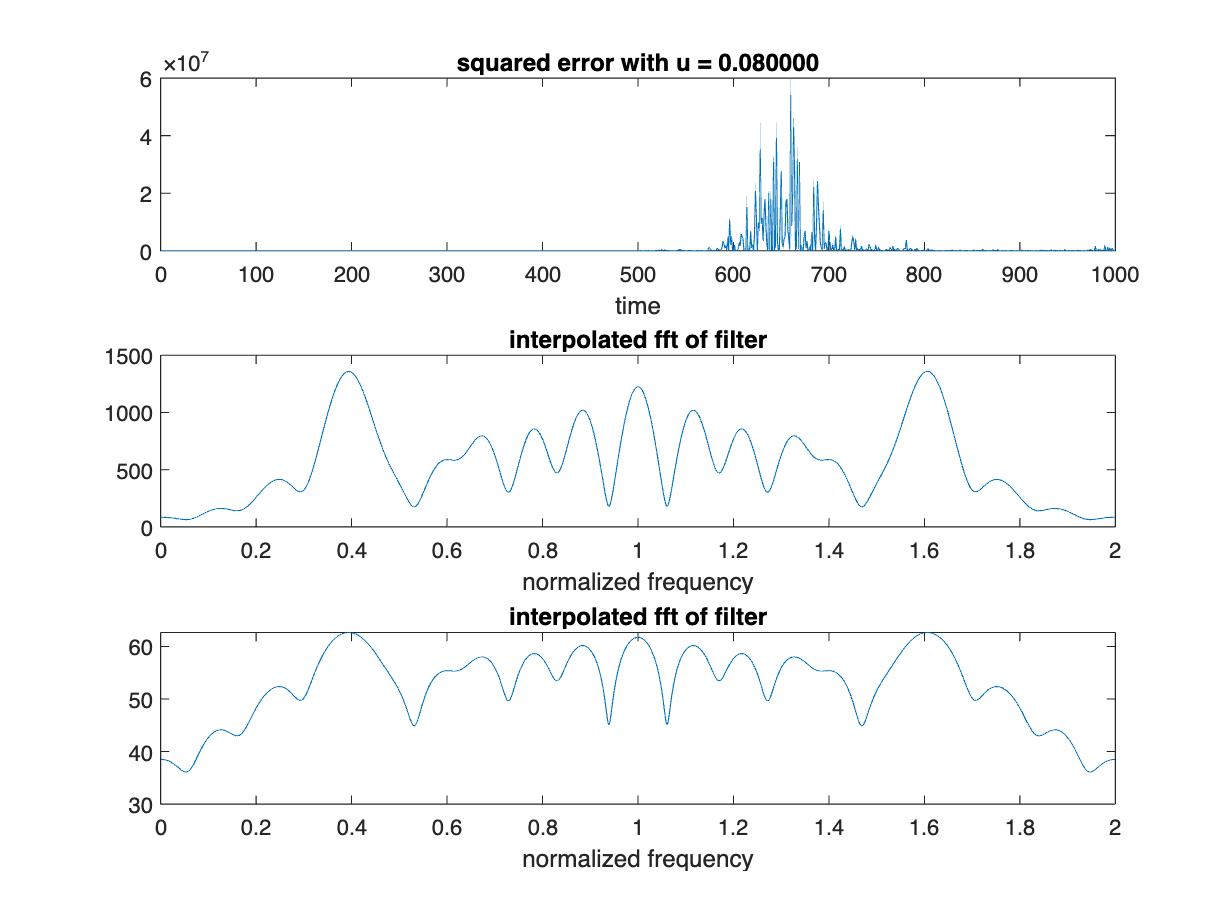

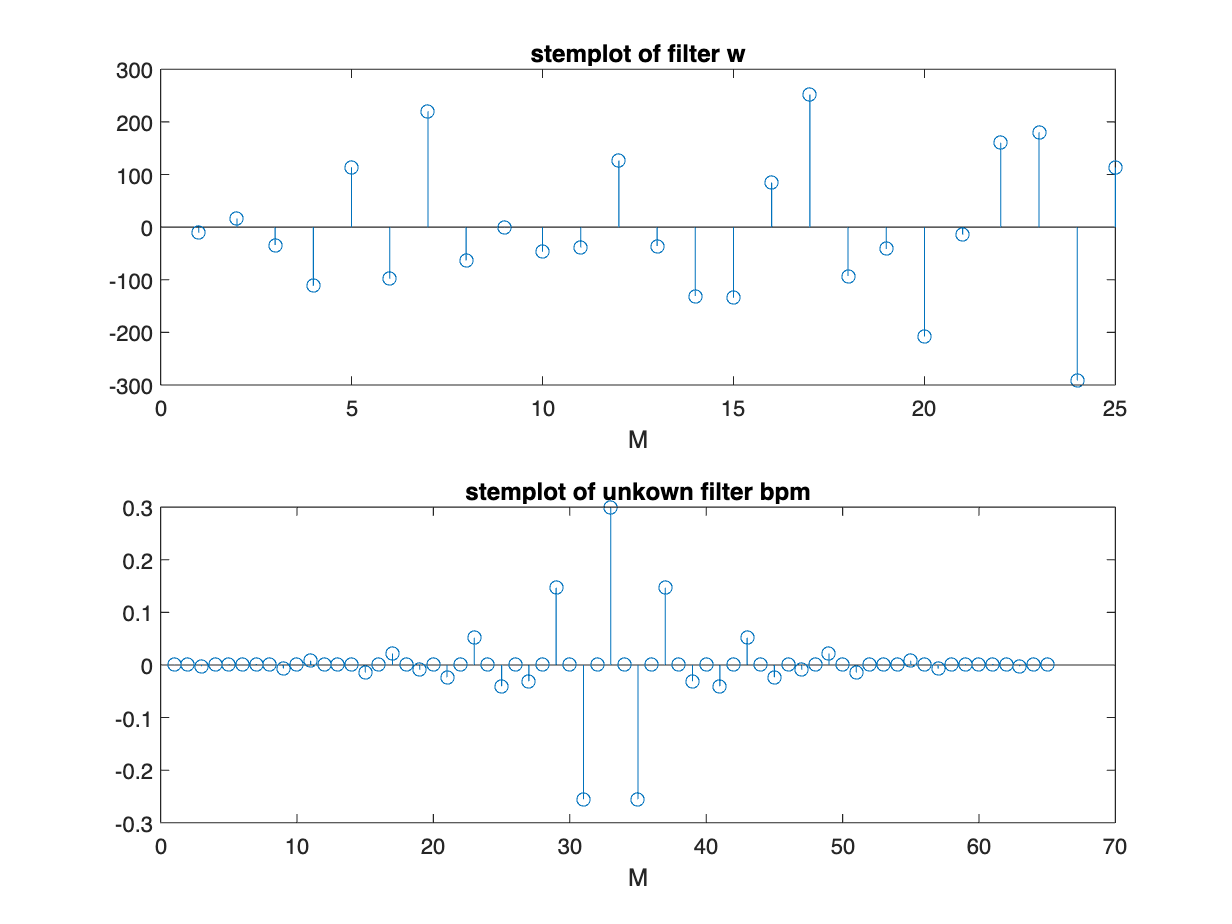

w = zeros(M, 1);
y_out = zeros(1, L);
err_out = zeros(1, L);
mu_arr = [0.001, 0.01, 0.05, 0.08, 0.0001];

for i=1:5
    mu = mu_arr(i);
    for n=M:L
        xn = x(n:-1:n-M+1)';
        yn=w' * xn;
        y_out(n) = yn;
        en = d(n) - yn;
        err_out(n) = en;
        w = w + mu*en*xn;
    end

    figure
    subplot(3,1,1);
    plot(err_out.*err_out)
    xlabel('time');
    title(sprintf("squared error with u = %f", mu))
    
    [H, fv] = freqz(w, 1, 2048, "whole");
    subplot(3,1,2);
    plot(fv/pi, abs(H))
    xlabel('normalized frequency');
    title('interpolated fft of filter')
    
    subplot(3,1,3);
    plot(fv/pi, 20*log10(abs(H)))
    xlabel('normalized frequency');
    title('interpolated fft of filter')
    
    figure
    subplot(2,1,1);
    stem(w)
    xlabel('M');
    title('stemplot of filter w')

    subplot(2,1,2);
    stem(b_pm)
    xlabel('M');
    title('stemplot of unkown filter bpm')

    w = zeros(M, 1);
    y_out = zeros(1, L);
    err_out = zeros(1, L);
end

**Does the error get reduced as the filter adapts?**

    No, the errors are consistantly high as L increases.

**Why is this filter not working well?**

    The stems plots are not matching. The fft's are also jagged.

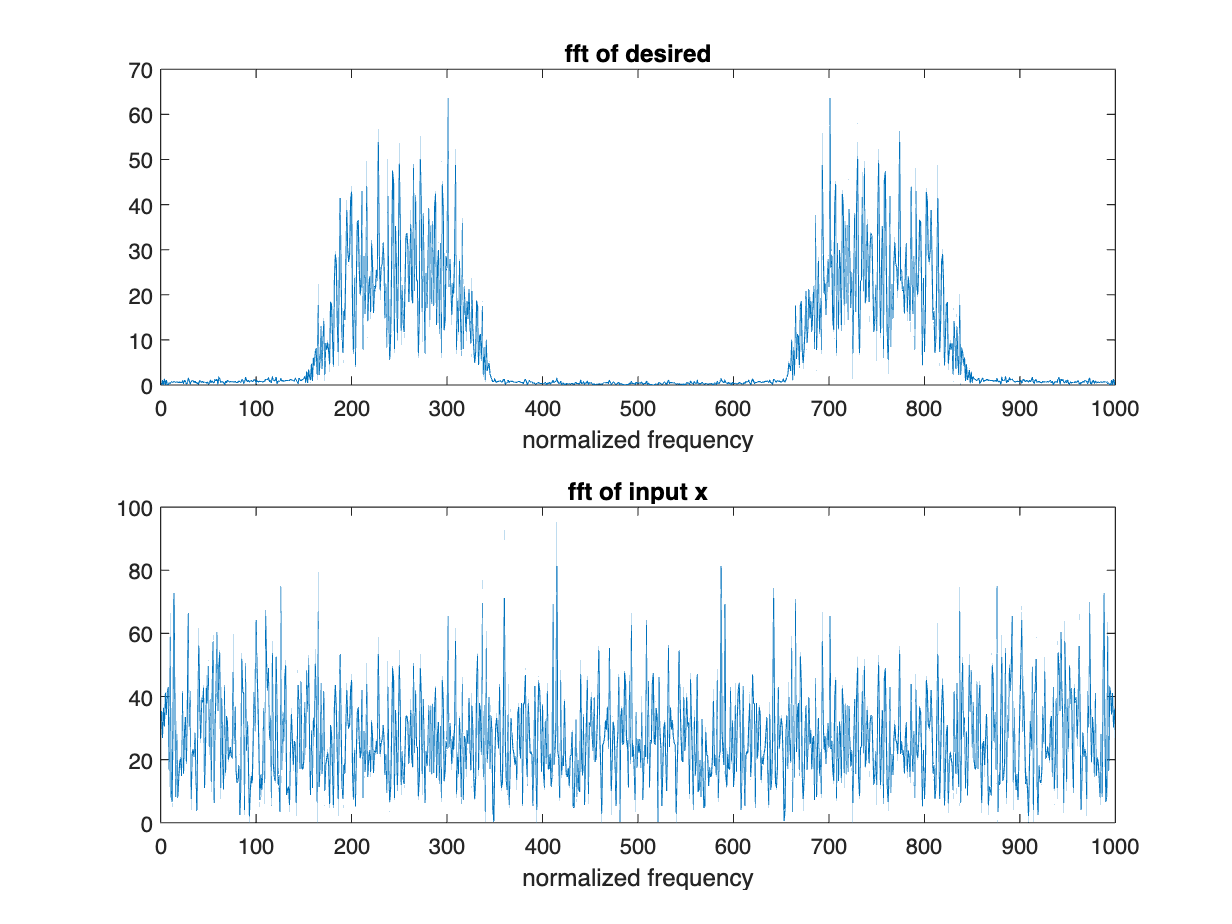

n_pm = 32;
b_pm = firpm(n_pm, f_pm, a_pm);
x = randn(1,L);
x_unk = conv(b_pm, x);
d = x_unk(1: end- length(b_pm)+1);

figure;
subplot(2,1,1);
plot(abs(fft(d)))
xlabel('normalized frequency');
title('fft of desired')

subplot(2,1,2);
plot(abs(fft(x)))
xlabel('normalized frequency');
title('fft of input x')

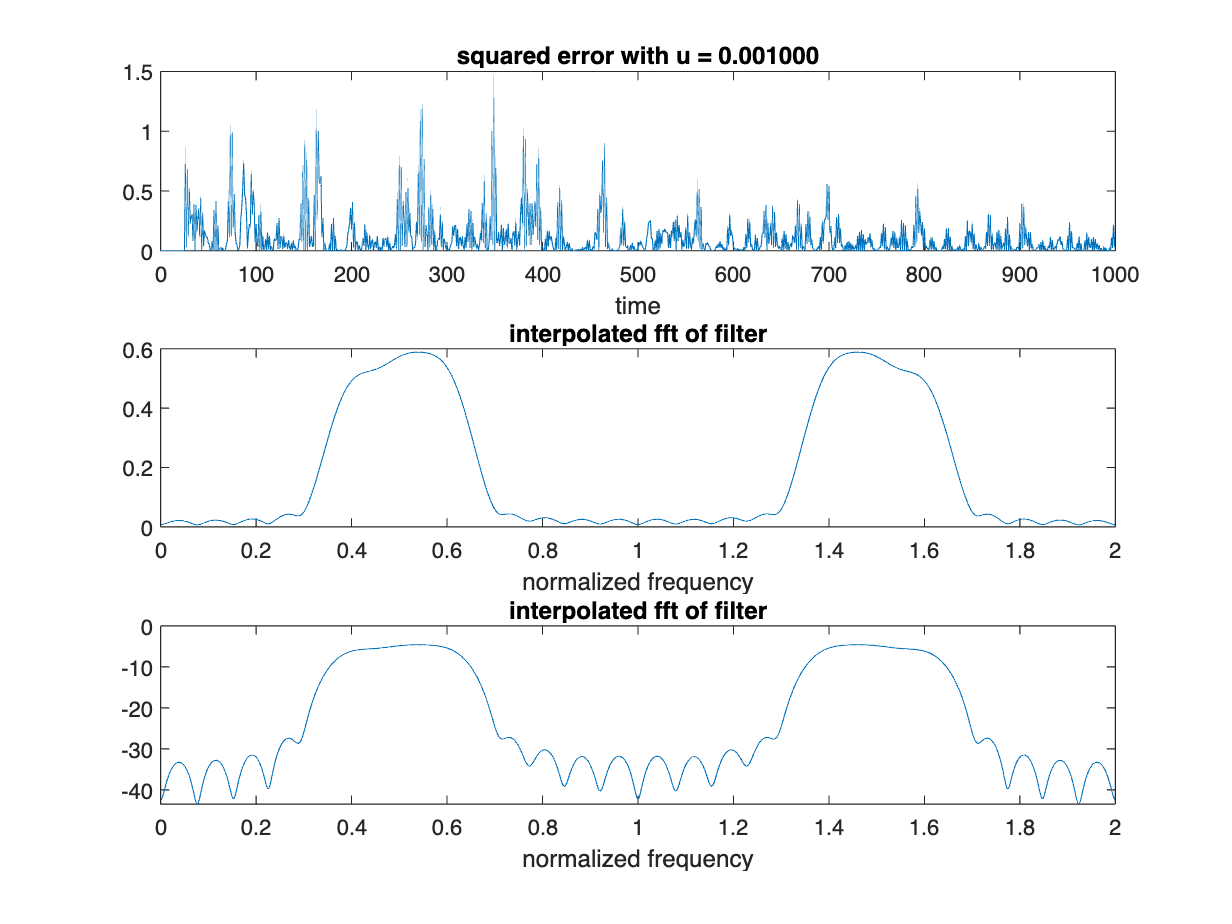

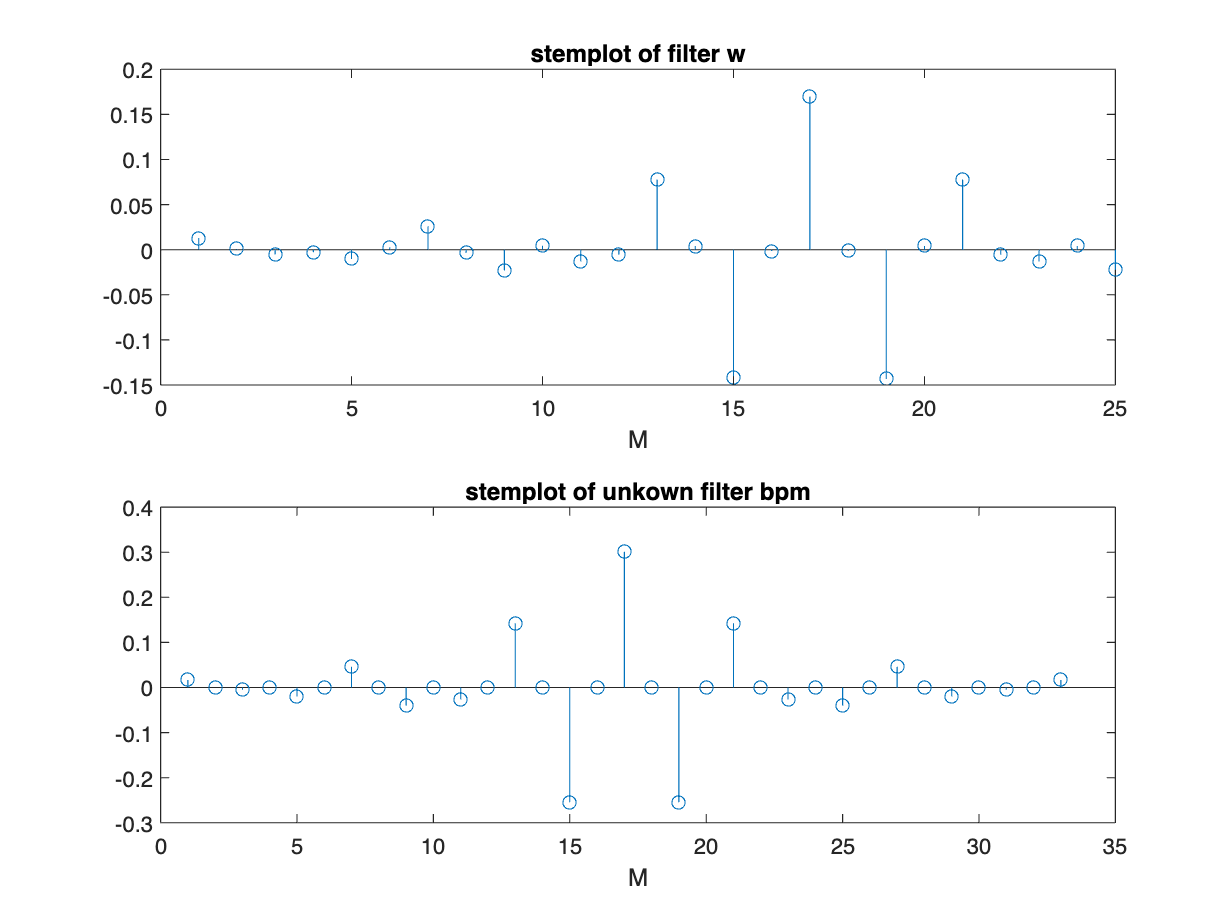

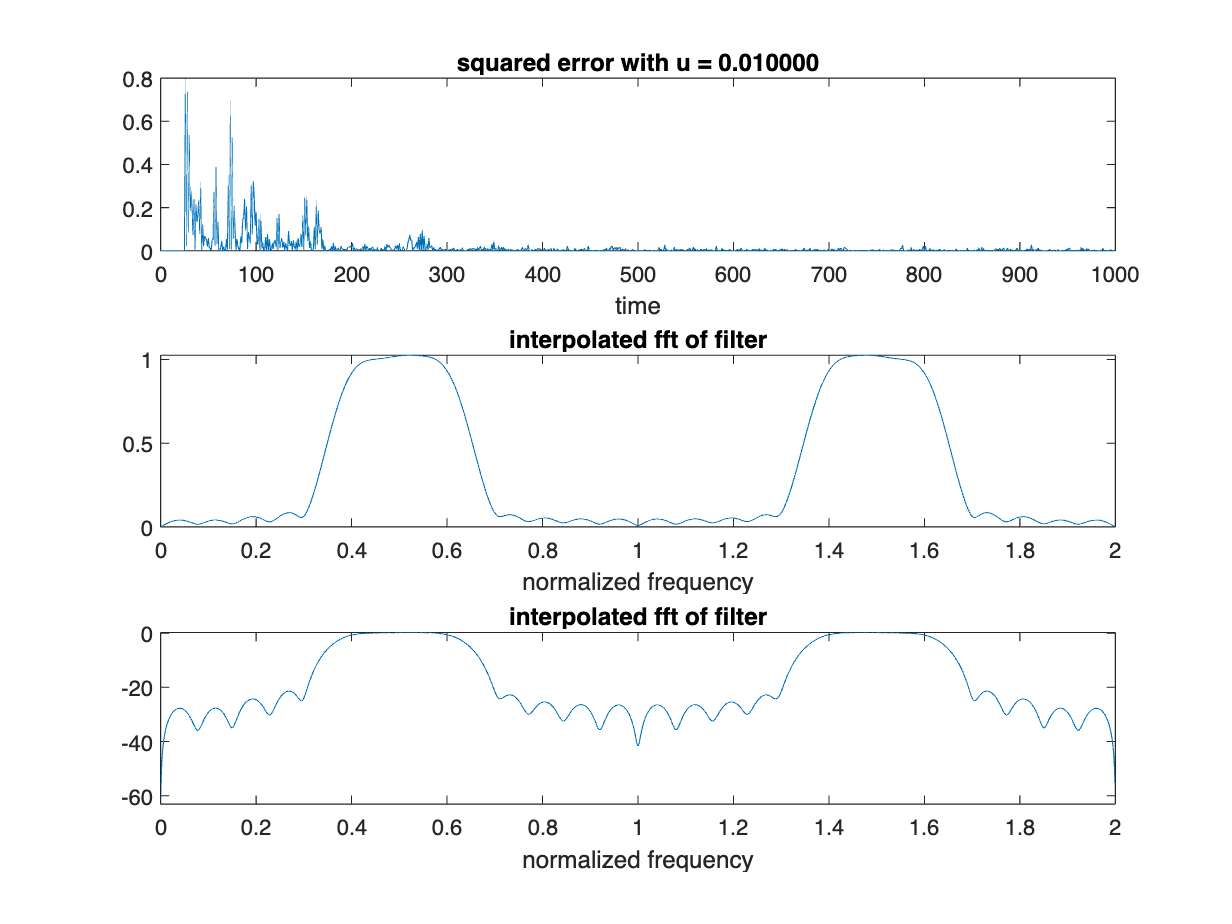

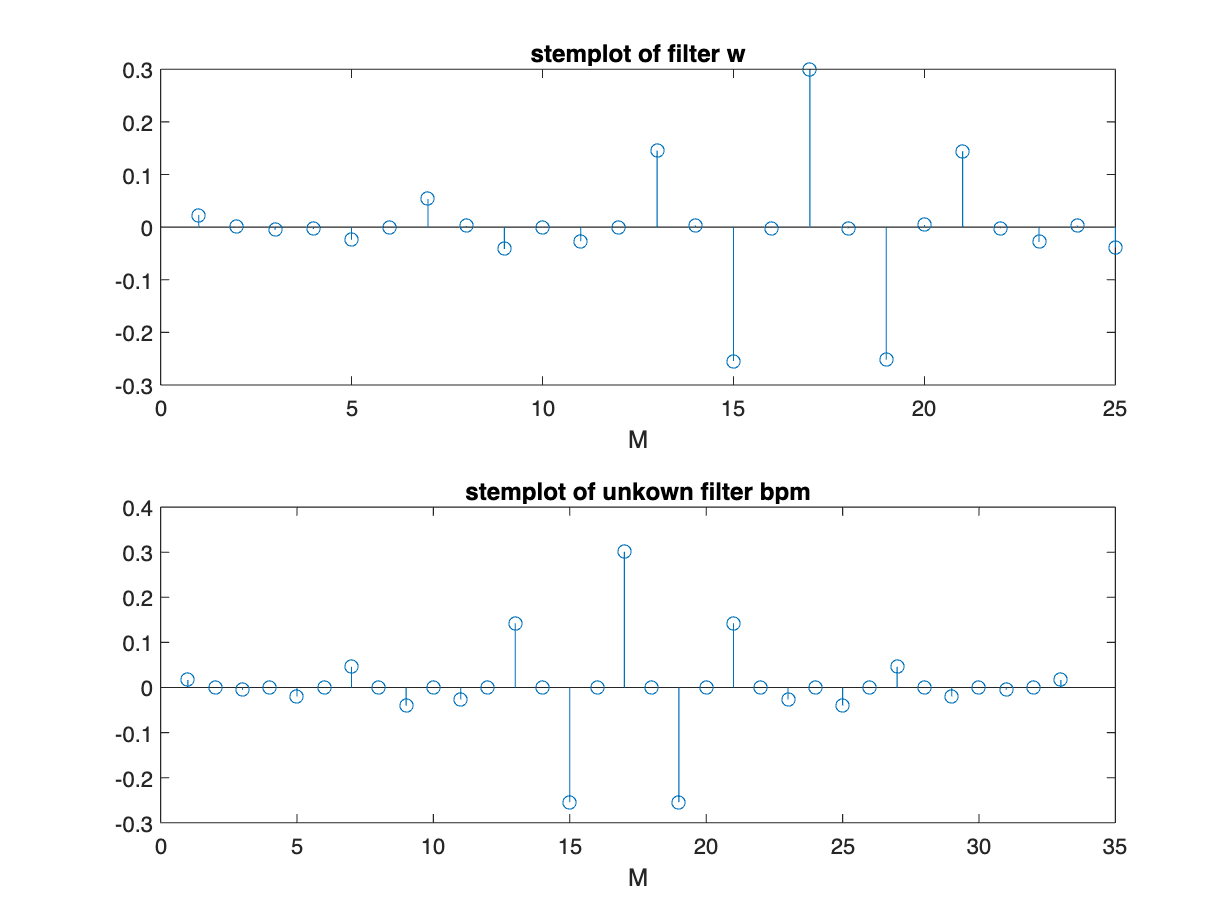

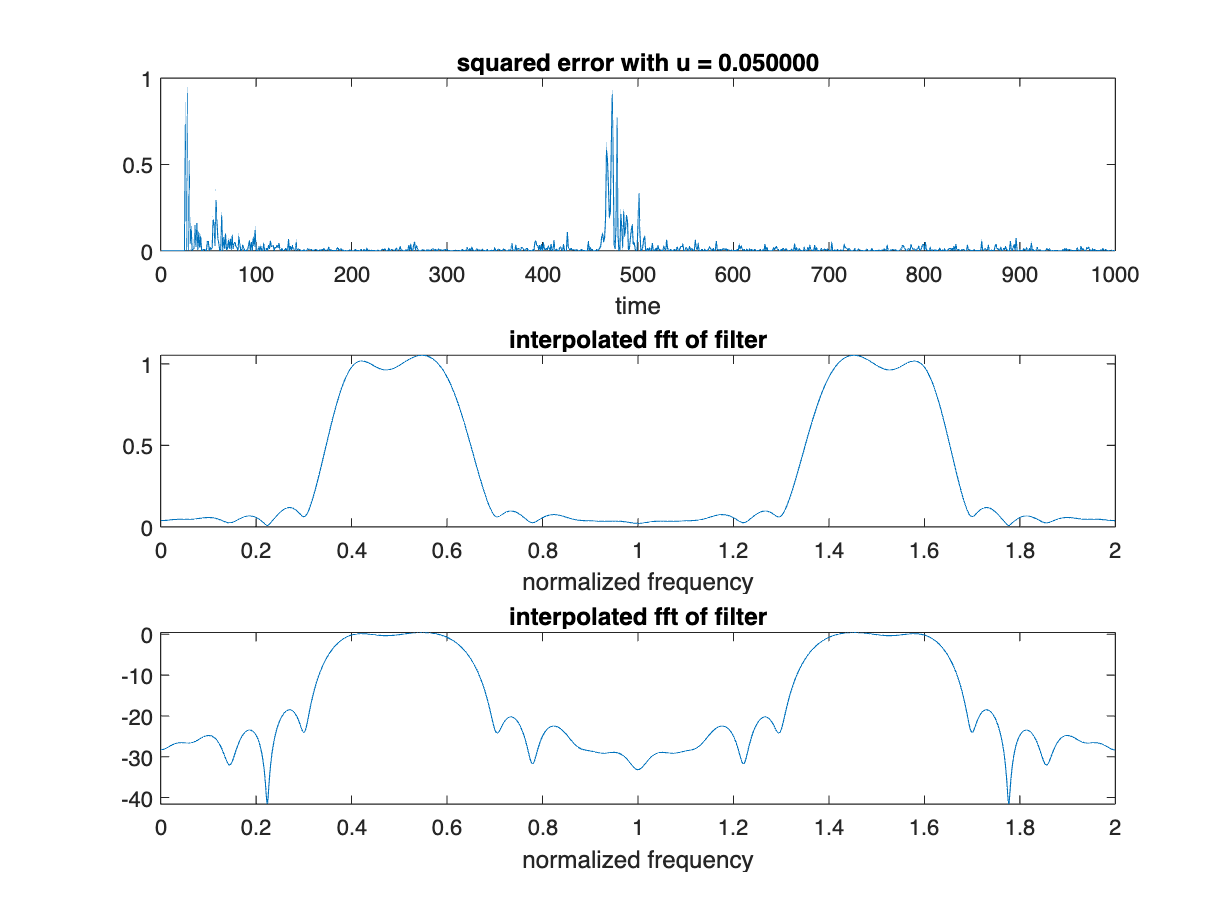

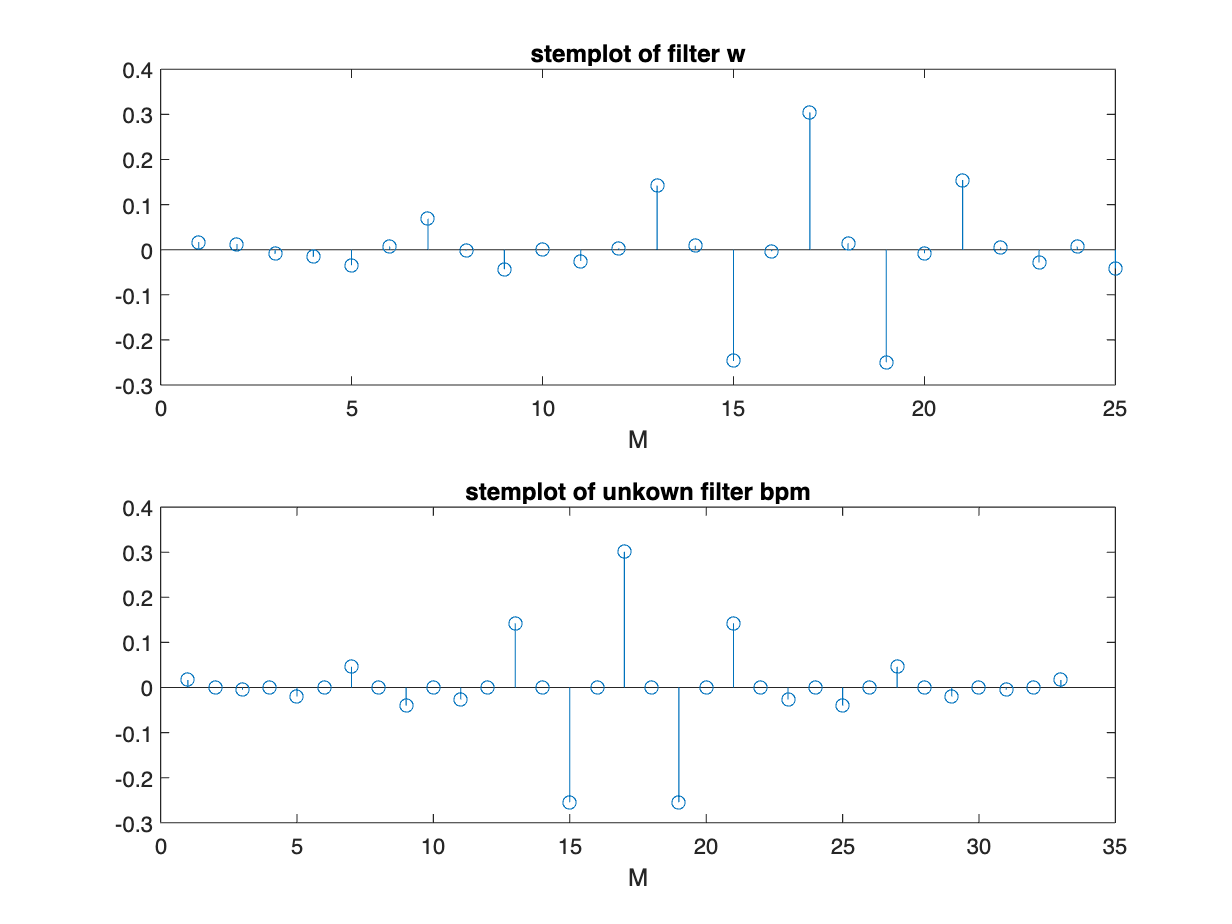

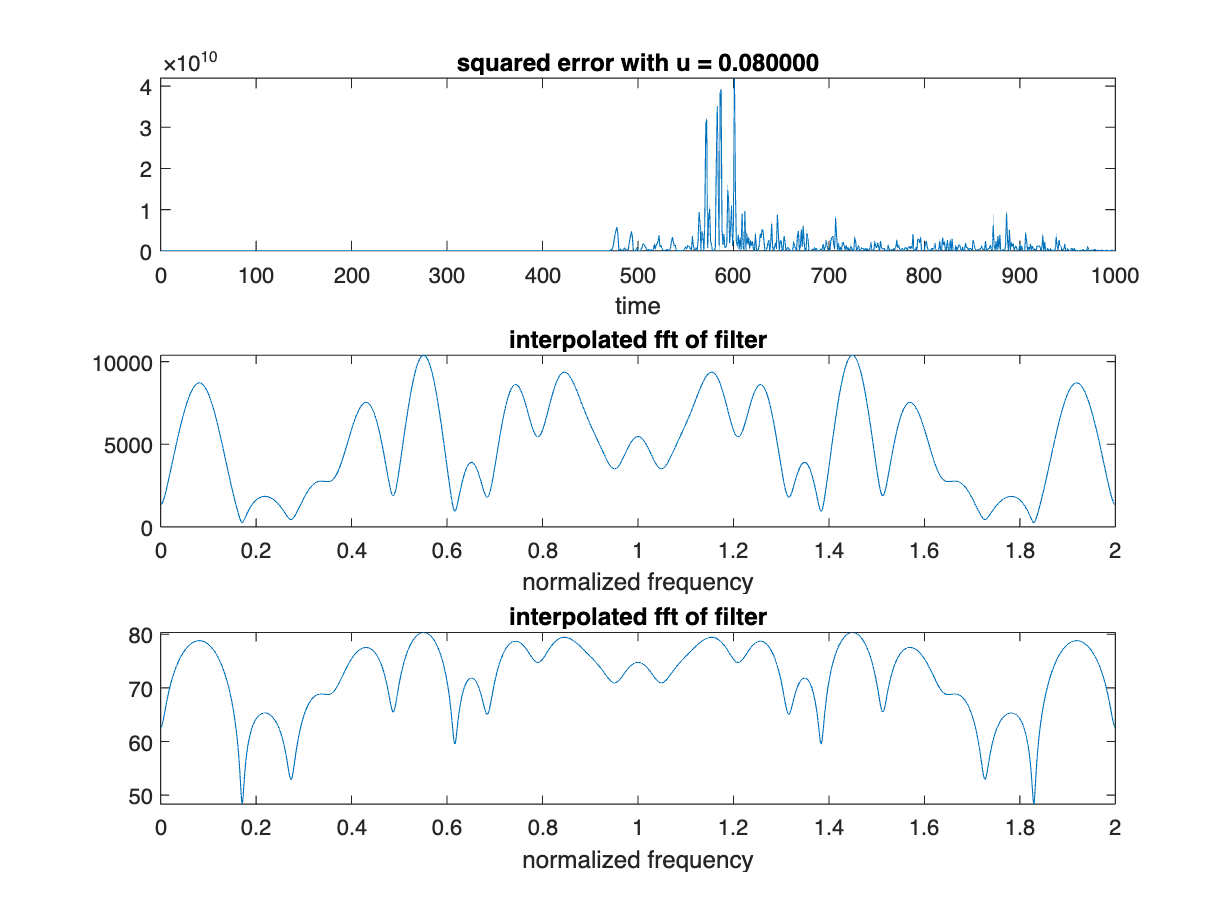

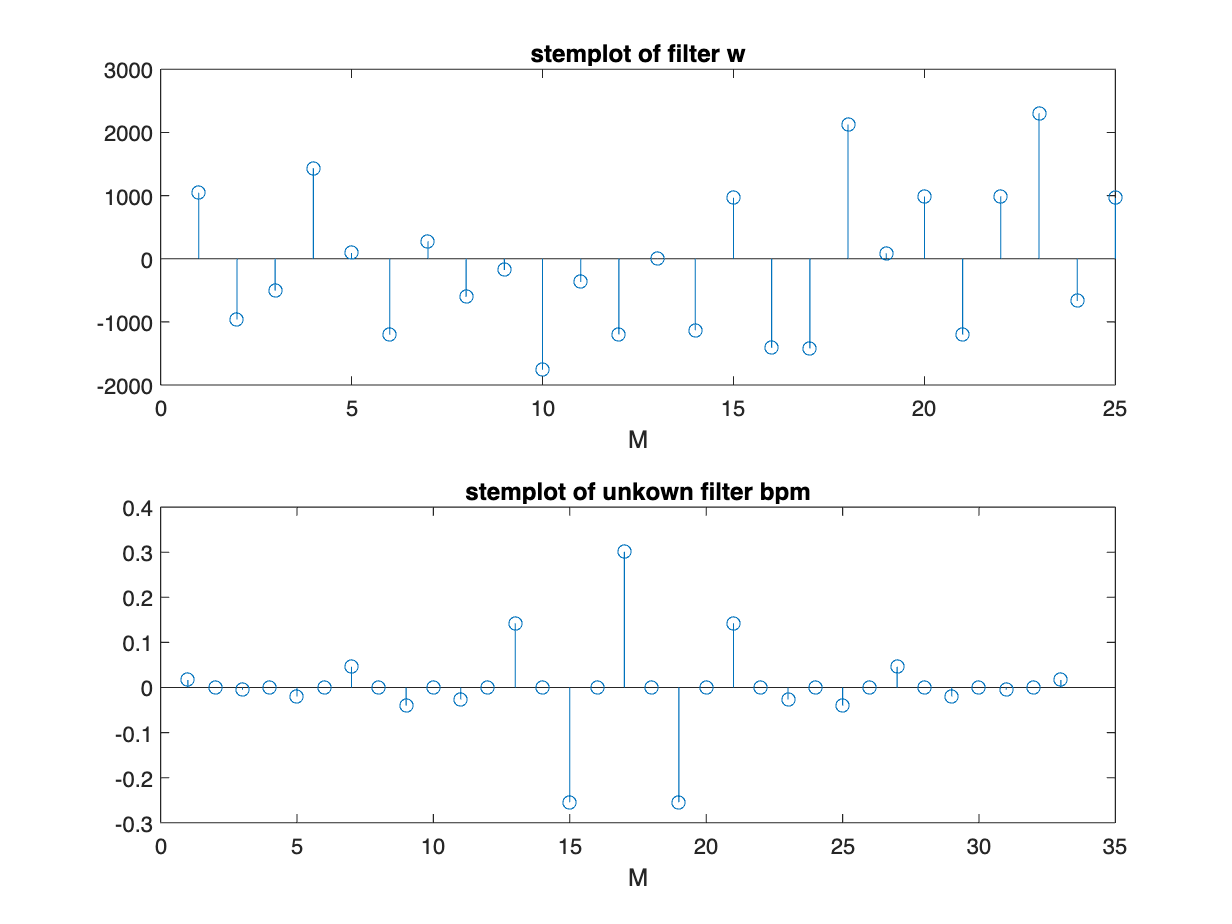

w = zeros(M, 1);
y_out = zeros(1, L);
err_out = zeros(1, L);
mu_arr = [0.001, 0.01, 0.05, 0.08, 0.0001];

for i=1:5
    mu = mu_arr(i);
    for n=M:L
        xn = x(n:-1:n-M+1)';
        yn=w' * xn;
        y_out(n) = yn;
        en = d(n) - yn;
        err_out(n) = en;
        w = w + mu*en*xn;
    end

    figure
    subplot(3,1,1);
    plot(err_out.*err_out)
    xlabel('time');
    title(sprintf("squared error with u = %f", mu))
    
    [H, fv] = freqz(w, 1, 2048, "whole");
    subplot(3,1,2);
    plot(fv/pi, abs(H))
    xlabel('normalized frequency');
    title('interpolated fft of filter')
    
    subplot(3,1,3);
    plot(fv/pi, 20*log10(abs(H)))
    xlabel('normalized frequency');
    title('interpolated fft of filter')
    
    figure
    subplot(2,1,1);
    stem(w)
    xlabel('M');
    title('stemplot of filter w')

    subplot(2,1,2);
    stem(b_pm)
    xlabel('M');
    title('stemplot of unkown filter bpm')

    w = zeros(M, 1);
    y_out = zeros(1, L);
    err_out = zeros(1, L);
end

**Explain why this change of n_pm made an improvement compared to the previous result. What other change might have improved the result?**

    The change of n_pm to 32 made an improvement because the order of the Parks McClellan filter was changed to 32 which allows it to better capture the higher ampltidues, since the original filter was order 25. 